# BME 499 - Final Project

David Chang and Mahmoud Komaiha

Due: April 24th, 2020

## Task 1 - Processing Data

### Reading in the table

cirrhosis = readtable('cirrhosis.csv');
% take out time temporarily, will add it back at end later
time = cirrhosis.time;
cirrhosis.time = [];
expandFigSize = [0 0 1000 700];

### Add the extra variables

% Log some key variables
cirrhosis.logalb = log(cirrhosis.albumin);
cirrhosis.logbil = log(cirrhosis.bili);
cirrhosis.logpro = log(cirrhosis.protime);

% Rearrange data to put time as last variable
cirrhosis.time = time;

### Store names and desc for later

% Make some variable descriptions
cirrhosis_desc = {'age','albumin','alkaline phosphatase','ascites','serum bilirubin','serum cholesterol', ...
    'edema treatment','hepatomegaly','platelets','prothrombin time','sex','aspartate aminotransferase','spiders',...
    'stage','censoring','treatment','trigycerides','urine copper','log albumin','log serum bilirubin',...
    'log prothrombin time','time'};
% Label the Categorial Variables
categVar = {'ascites','edema','hepato','sex','spiders','stage','trt'};
% Subset key variables w/o log
subset = {'age','albumin','bili','alkphos','chol','ast','protime',...
    'platelet','spiders','hepato','ascites','edema'};
% Subset key variables w/ generated log features
subset_log = {'age','albumin','bili','alkphos','chol','ast','protime','platelet',...
    'spiders','hepato','ascites','edema','logalb','logbil','logpro'};
cirrhosis.Properties.VariableDescriptions = cirrhosis_desc;
cirrhosis_names = cirrhosis.Properties.VariableNames;
head(cirrhosis)

ans = 8×22 table
     age      albumin    alkphos    ascites    bili    chol    edema    hepato    platelet    protime    sex     ast      spiders    stage    status    trt    trig    copper    logalb      logbil     logpro    time
    ______    _______    _______    _______    ____    ____    _____    ______    ________    _______    ___    ______    _______    _____    ______

## Task 2 - Exploratory Phase

### Summarize data

cirr_summary = summary(cirrhosis);
N = numel(cirrhosis.Properties.VariableNames);
temp_table = struct('Min',zeros(N,1),'Max',zeros(N,1),'Range',zeros(N,1),...
                    'Median',zeros(N,1),'Mean',zeros(N,1),'NumMissing',zeros(N,1));
for i=1:N
    temp_struct              = cirr_summary.(cirrhosis_names{i});
    temp_table.Min(i)        = temp_struct.Min;
    temp_table.Max(i)        = temp_struct.Max;
    temp_table.Mean(i)       = mean(cirrhosis.(cirrhosis_names{i}));
    temp_table.Median(i)     = temp_struct.Median;
    temp_table.Range(i)      = temp_struct.Max - temp_struct.Min;
    temp_table.NumMissing(i) = temp_struct.NumMissing;
end
sumTable = table(cirrhosis_names', ...
      cirrhosis_desc', ...
      temp_table.Min, ...
      temp_table.Max, ...
      temp_table.Mean, ...
      temp_table.Median, ...
      temp_table.Range, ...
      temp_table.NumMissing, ...
      'VariableNames',{'VarName','VarDesc','Min','Max','Mean','Median','Range','NumMissing'})

sumTable = 22×8 table
      VarName                  VarDesc                 Min       Max        Mean      Median    Range     NumMissing
    ____________    ______________________________    ______    ______    ________    ______    ______    __________

    {'age'     }    {'age'                       }    26.278    78.439      50.019    49.795    52.162         0    
    {'albumin' }    {'albumin'                   }      1.96      4.64        3.52      3.55      2.68         0    
    {'alkphos' }    {'alkaline phosphatase'      }       289     13862      1982.7      1259     13573         0    
    {'ascites' }    {'ascites'                   }         0         1    0.076923         0         1         0    
   

### Clean up and setup data for unupervised and supervised learning

**Time and status are the two dependent variables. This cleanup is done to make separate datasets so that the two dependent variables are not in the same dataset**.

cirrhosis = original dataset with missing values removed

cirrhosis_log = log(time) and status is removed - for linear regression, lasso, stepwise and RF_regression models

cirrhosis_status = time is removed - for PCA, k-means clustering, classification, so logistic regression and RF_classification models

nMissingRows = sum(any(ismissing(cirrhosis),2))

nMissingRows = 36

cirrhosis = rmmissing(cirrhosis);
cirrhosis_log = cirrhosis;
cirrhosis_log.time = log(cirrhosis_log.time);
cirrhosis_log = removevars(cirrhosis_log,{'status'});
cirrhosis_log_names = cirrhosis_log.Properties.VariableNames;
cirrhosis_status = cirrhosis(:,1:end-1);
status = cirrhosis_status.status;
cirrhosis_status.status = [];
cirrhosis_status.status = status > 1;
cirrhosis_status_names = cirrhosis_status.Properties.VariableNames;

### Standardize Data with Z score

Toggle on and off with comments

Rerun and save different version of output when doing this

% status = cirrhosis_status.status;
% cirrhosis = zscore(table2array(cirrhosis));
% cirrhosis = array2table(cirrhosis,"VariableNames",cirrhosis_names);
% cirrhosis_log = zscore(table2array(cirrhosis_log));
% cirrhosis_log = array2table(cirrhosis_log,"VariableNames",cirrhosis_log_names);
% array2table(cirrhosis_log,"VariableNames",cirrhosis_log_names);
% cirrhosis_status = zscore(table2array(cirrhosis_status));
% cirrhosis_status = array2table(cirrhosis_status,"VariableNames",cirrhosis_status_names);
% cirrhosis_status.status = status;

### Feature Histograms

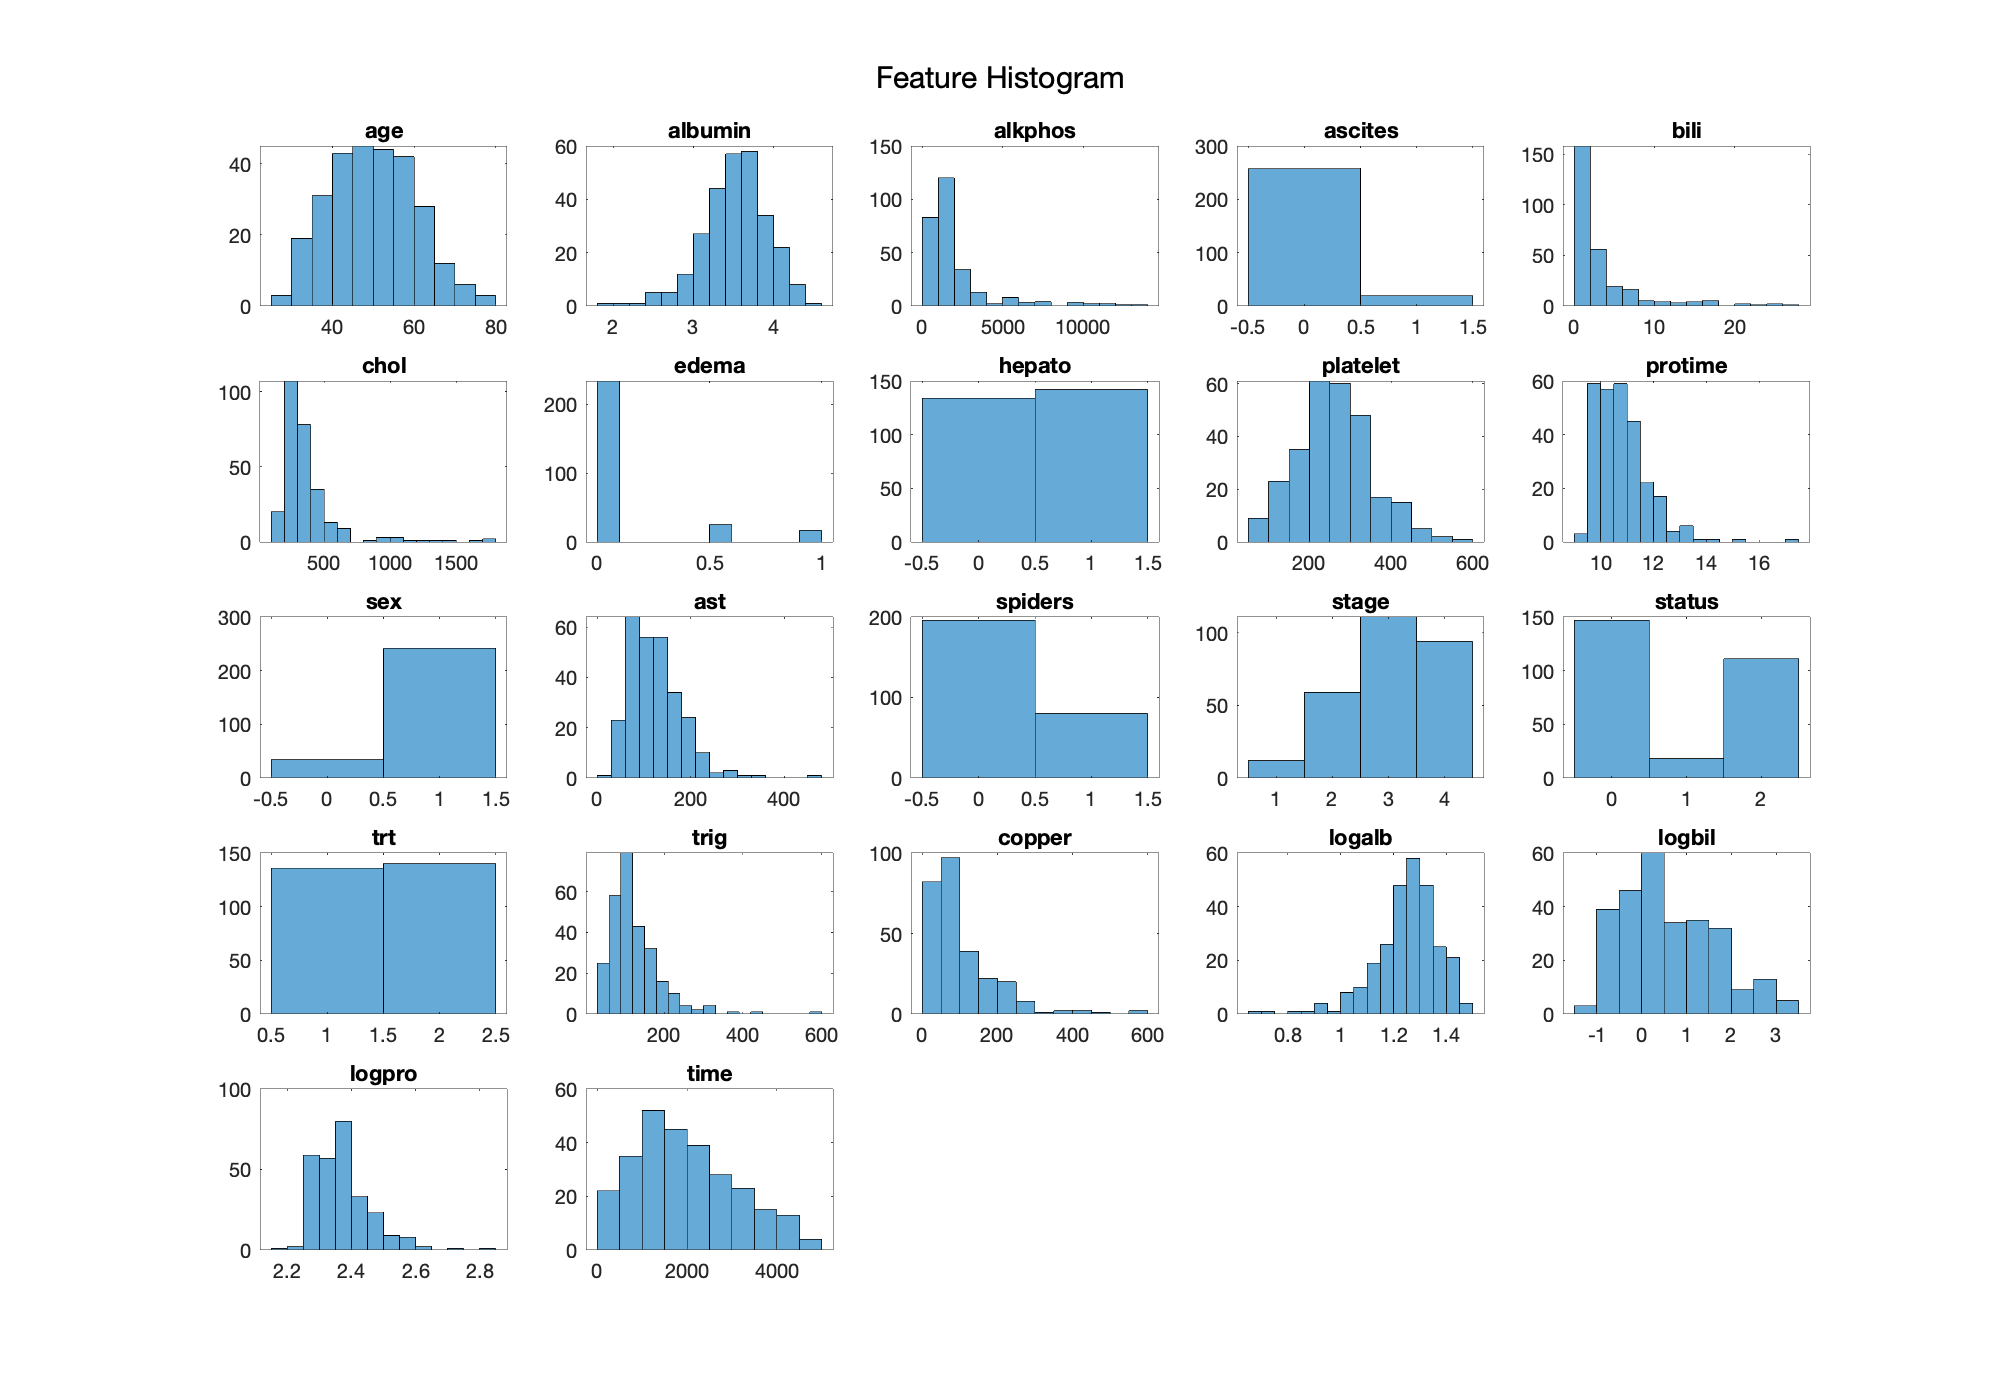

f = figure();
set(f, 'Position', expandFigSize)
for i=1:size(cirrhosis,2)
    subplot(5,5,i)
    histogram(cirrhosis.(i))
    title(cirrhosis_names{i})
end
sgtitle("Feature Histogram")

### Boxplot

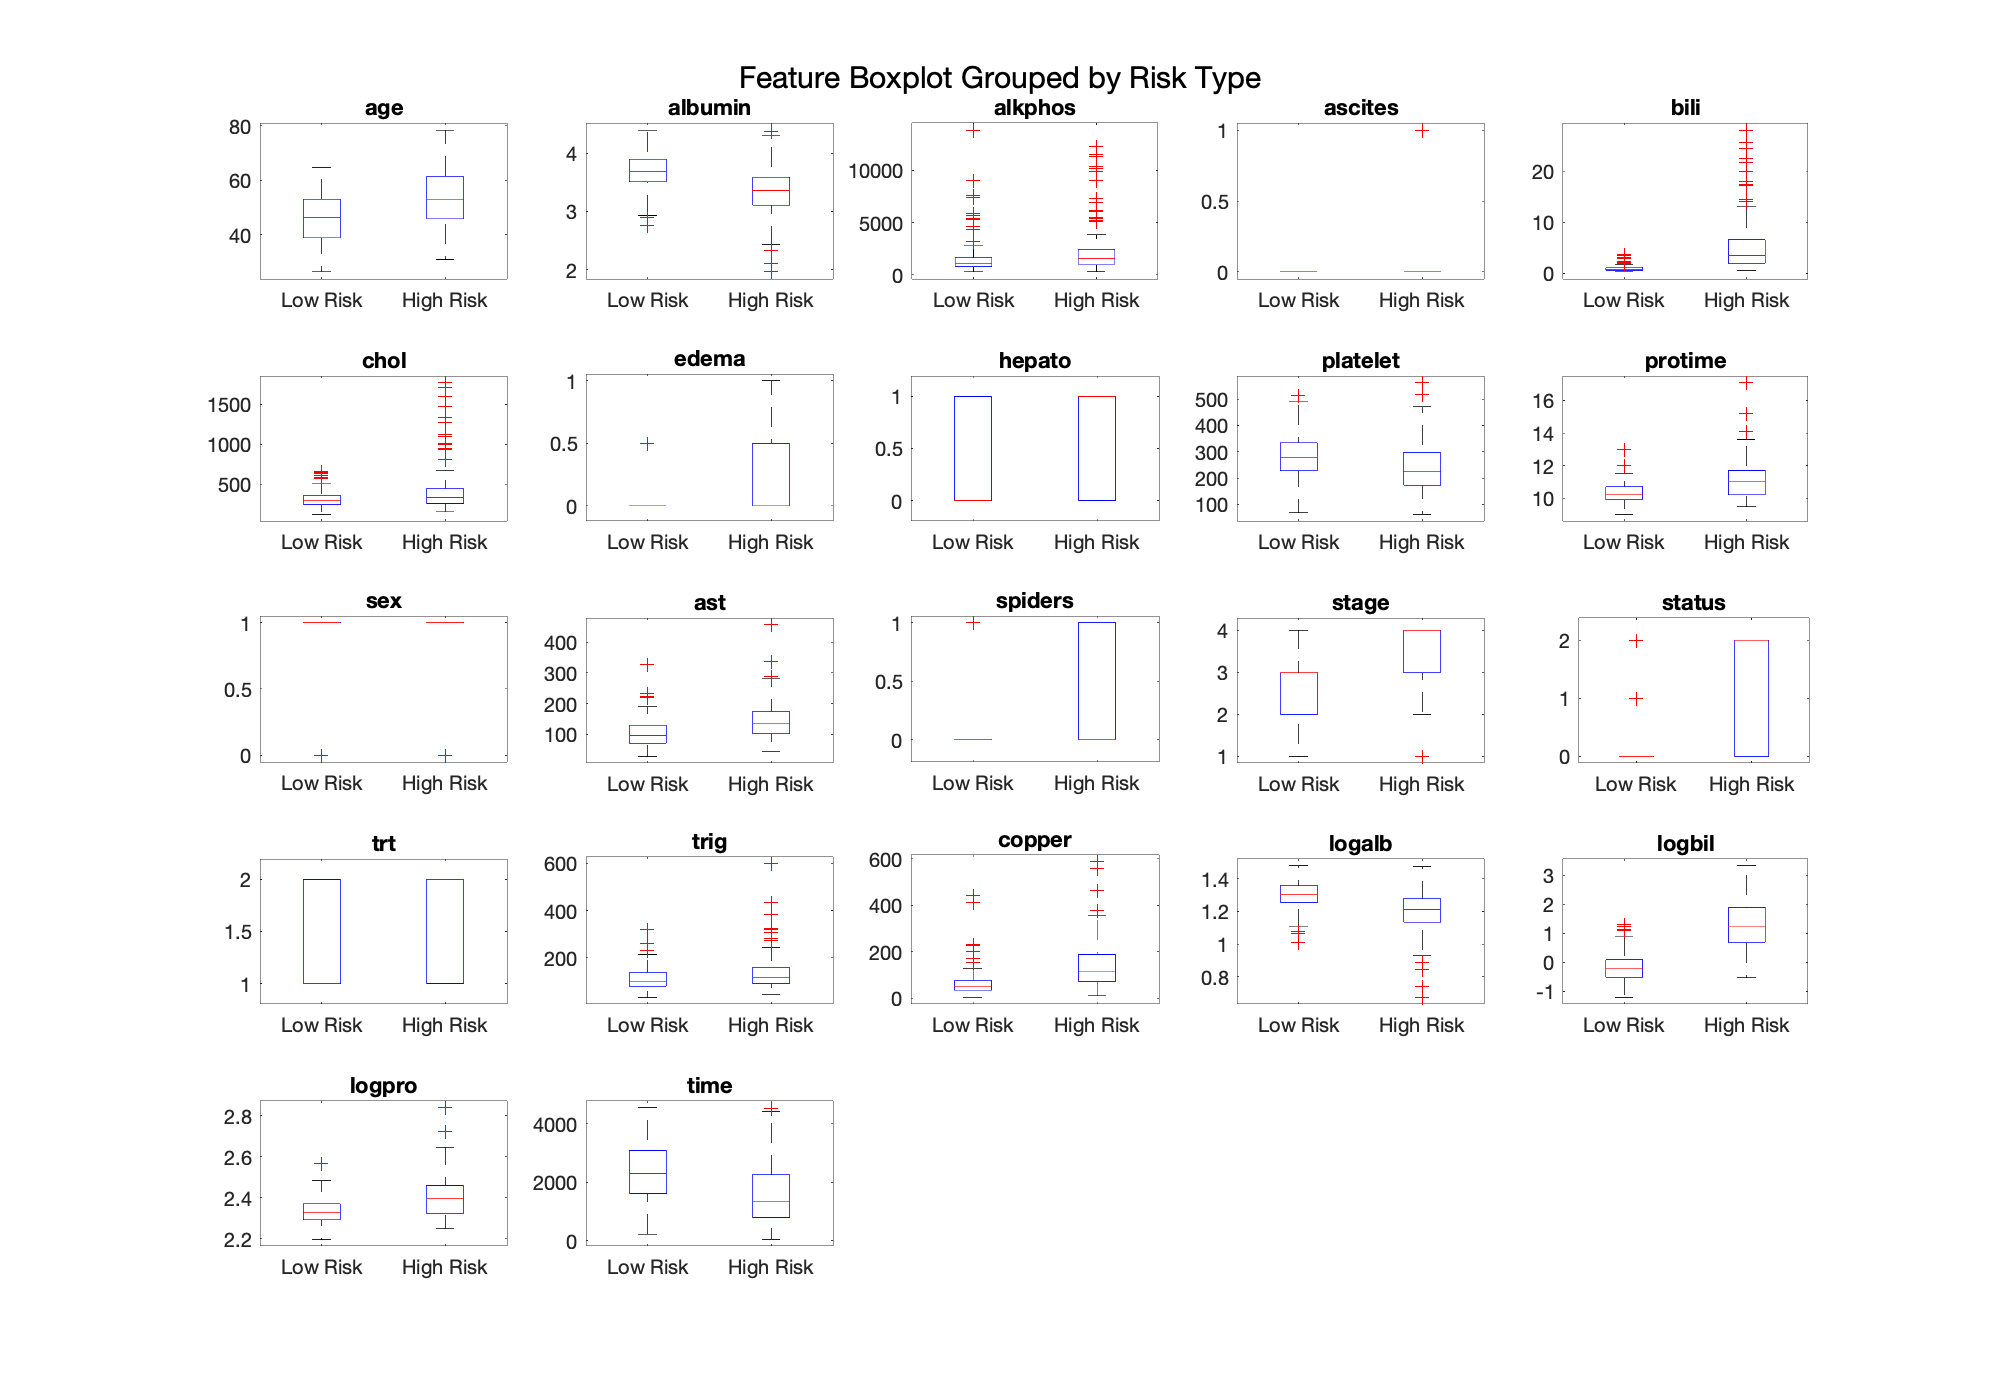

% Risk score computation as described in Cirrhosis paper
mayoFinalR = 0.871*cirrhosis.logbil ...
   - 2.53*cirrhosis.logalb ...
   + 0.039*cirrhosis.age ...
   + 2.38*cirrhosis.logpro ...
   + 0.859*cirrhosis.edema;
% Scatterplot subset by risk high risk -> decreased survivability
f = figure();
set(f, 'Position', expandFigSize)
for i=1:size(cirrhosis,2)
    subplot(5,5,i)
    boxplot(cirrhosis.(i),mayoFinalR >= median(mayoFinalR),'Labels',{'Low Risk','High Risk'})
    title(cirrhosis_names{i})
end
sgtitle("Feature Boxplot Grouped by Risk Type")

### Scatter time vs. feature

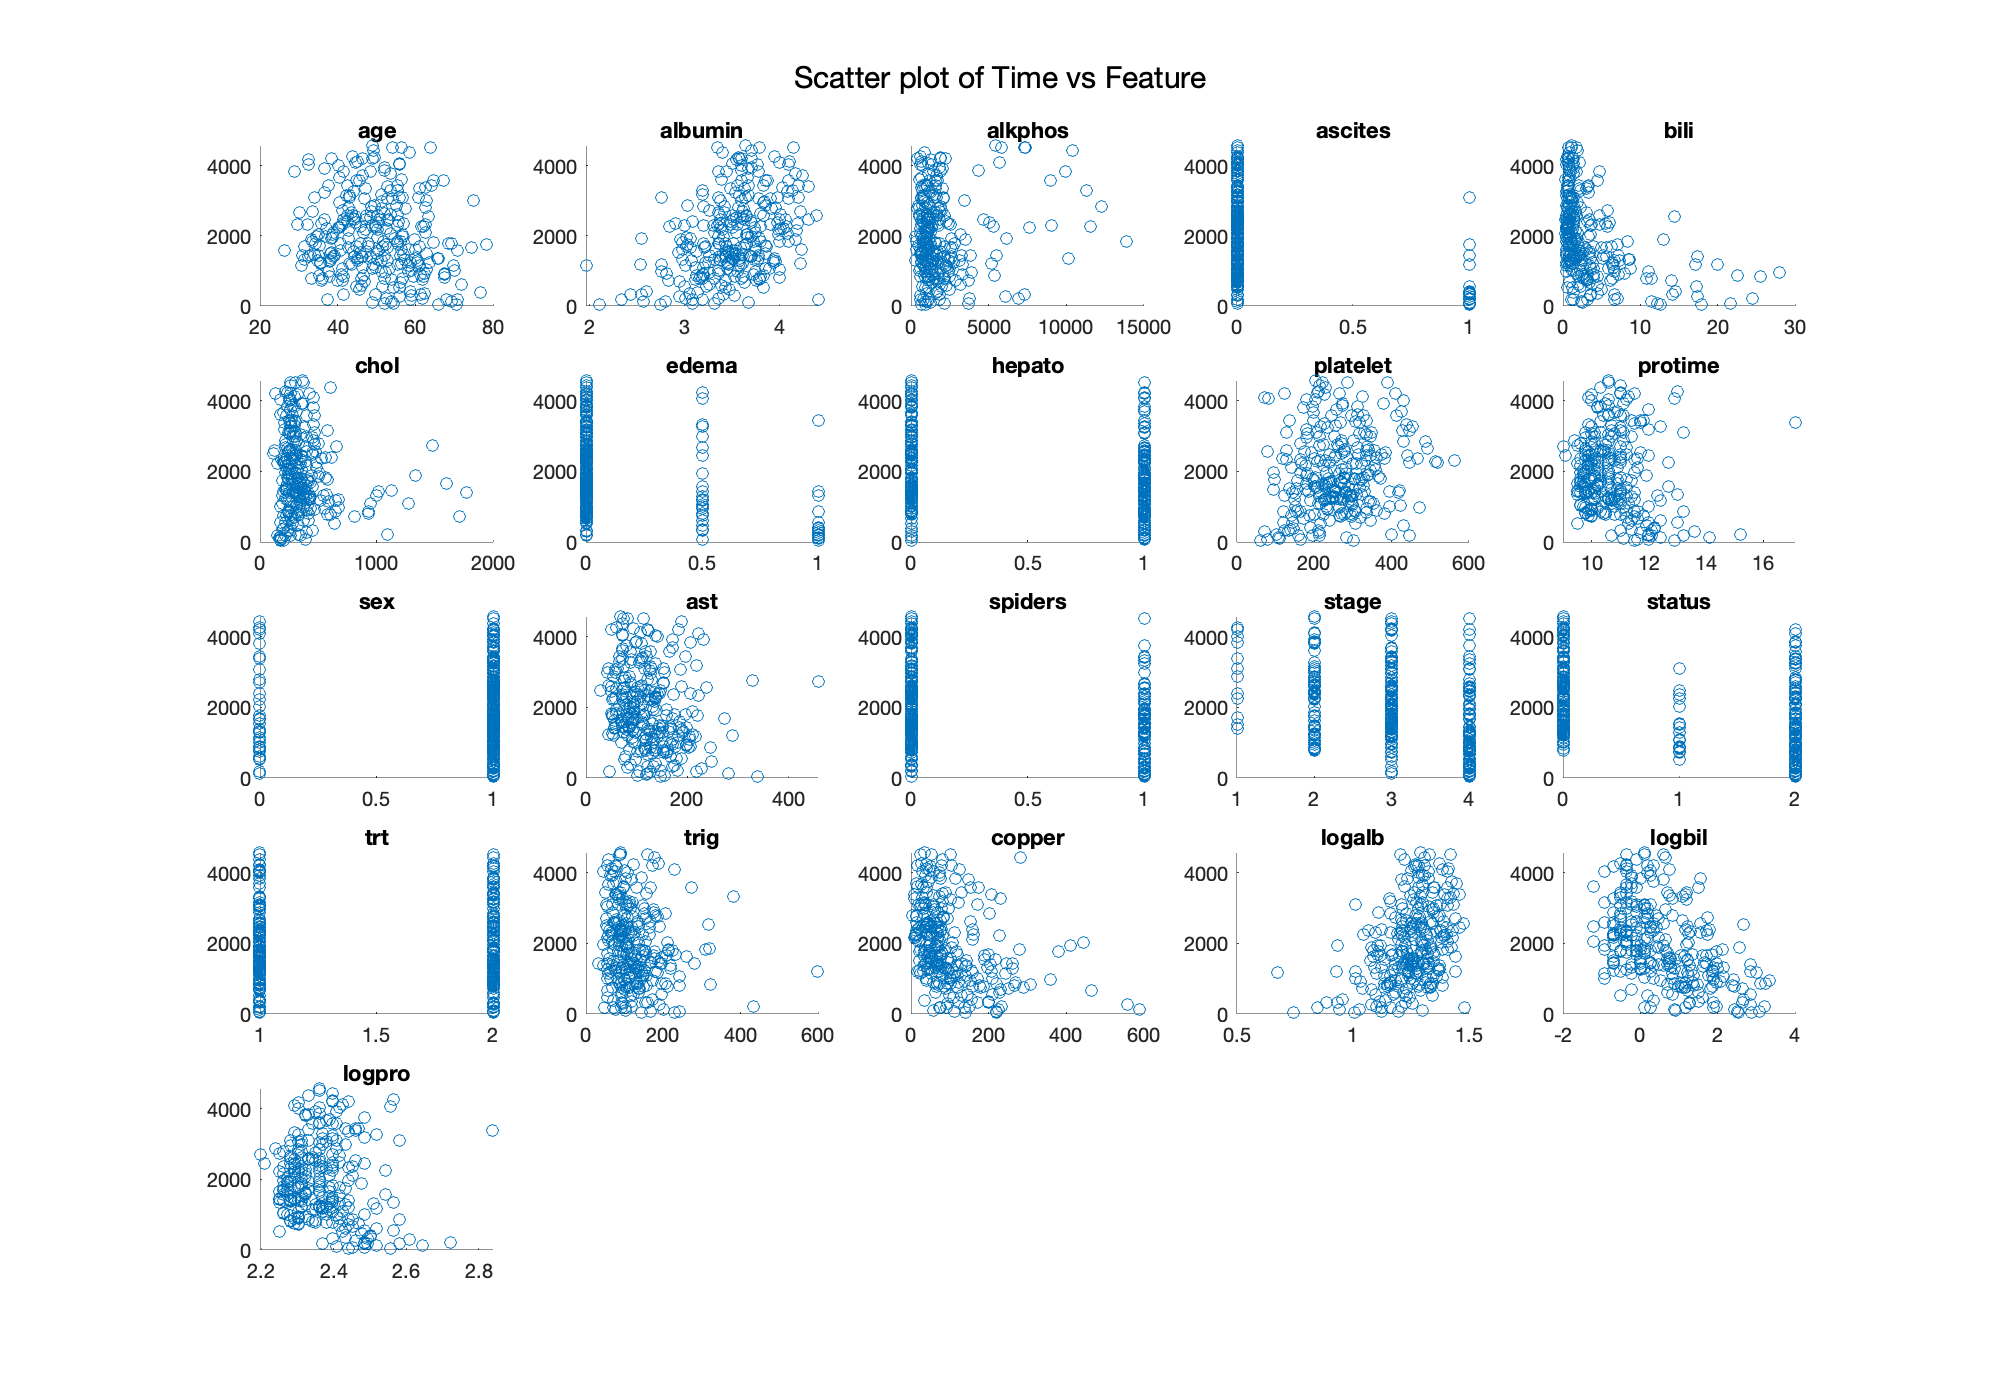

f = figure();
set(f, 'Position', expandFigSize)
for i=1:size(cirrhosis,2)-1
    subplot(5,5,i)
    scatter(cirrhosis.(i),cirrhosis.time)
    title(cirrhosis_names{i})
end
sgtitle("Scatter plot of Time vs Feature")

### Scatter log time vs. feature

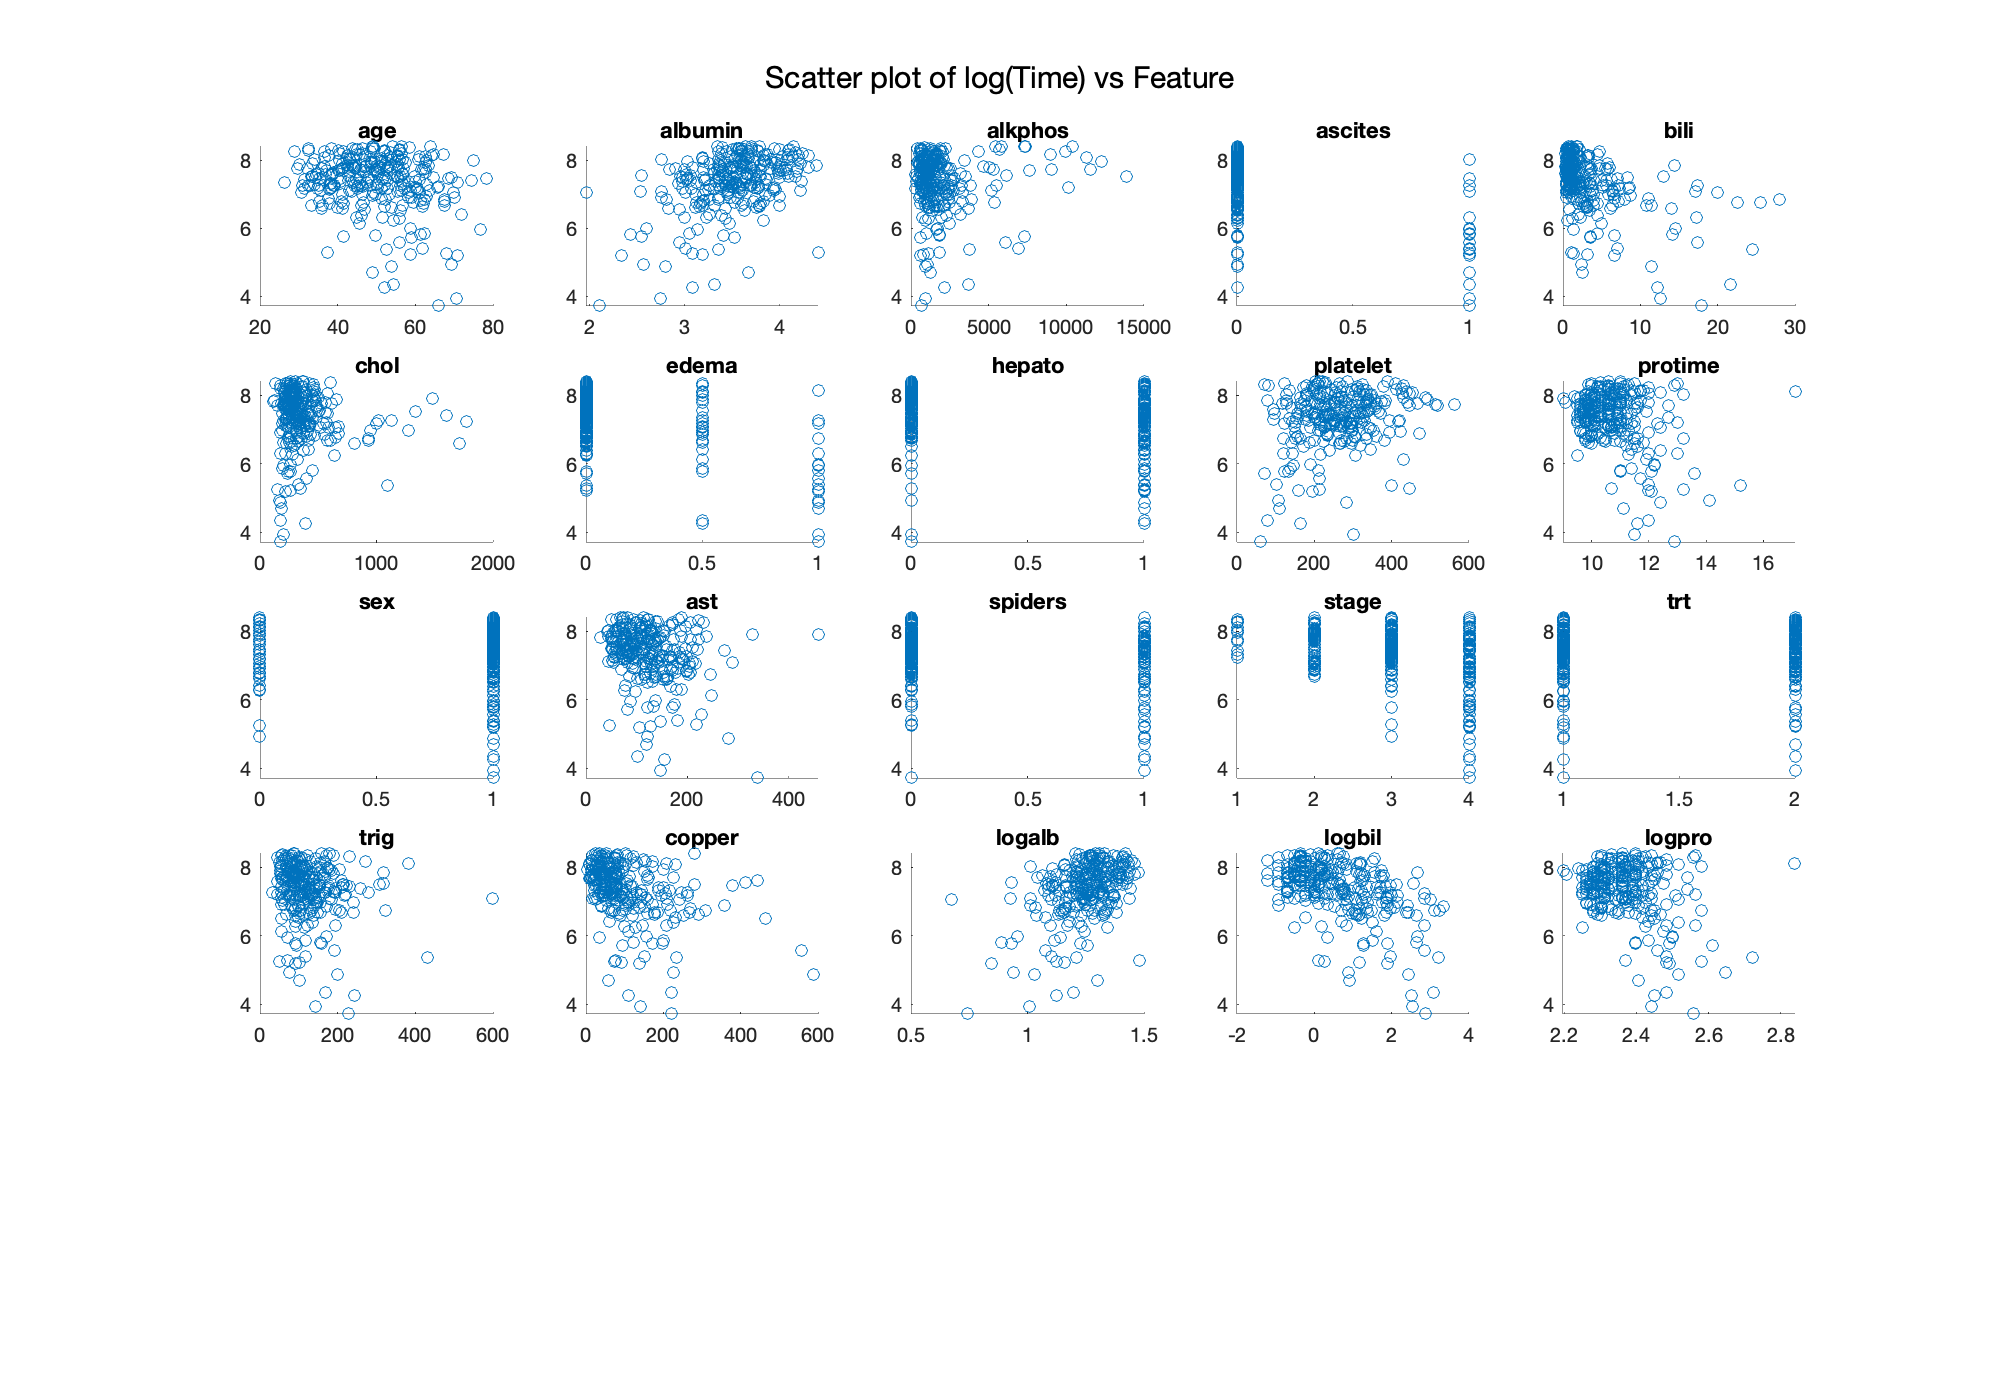

f = figure();
set(f, 'Position', expandFigSize)
for i=1:size(cirrhosis_log,2)-1
    subplot(5,5,i)
    scatter(cirrhosis_log.(i),cirrhosis_log.time)
    title(cirrhosis_log_names{i})
end
sgtitle("Scatter plot of log(Time) vs Feature")

## Task 3 - Statistical Analysis

### Pairwise spearman rank correlations

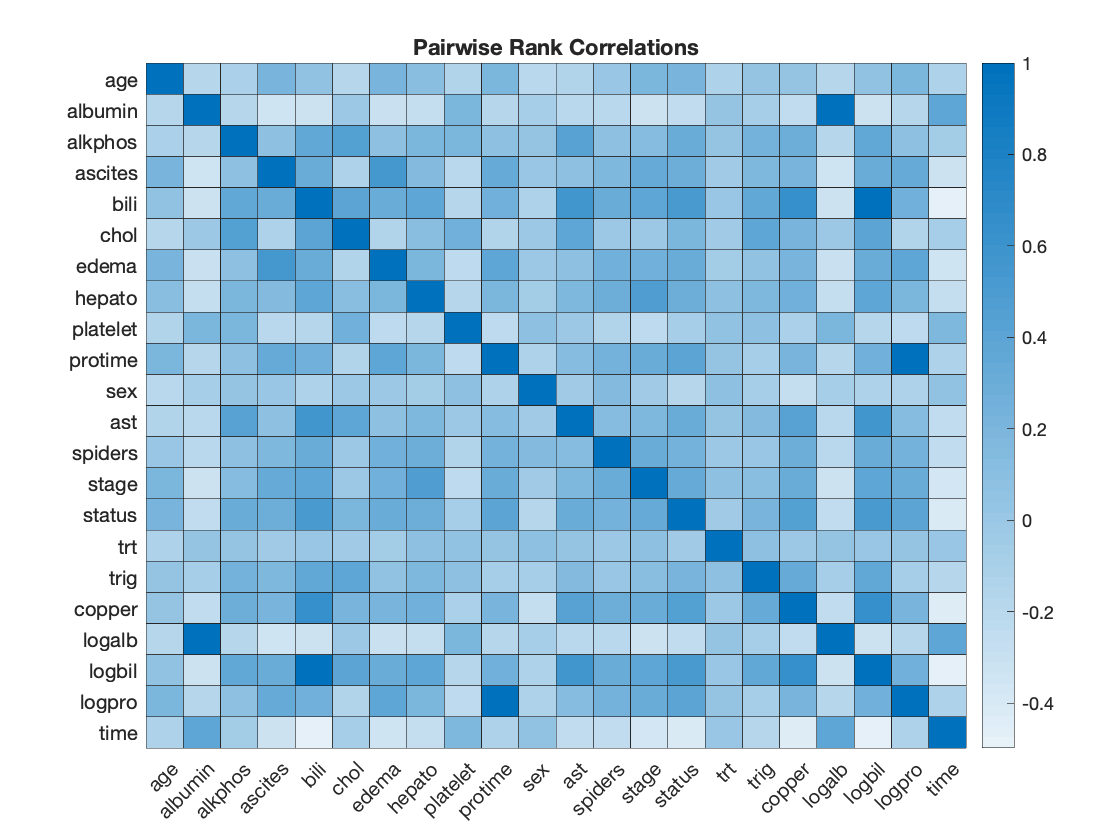

figure();
[R_rank,P_rank] = corr(table2array(cirrhosis),'Type','Spearman','rows','complete');
r_rank_map = heatmap(R_rank);
title('Pairwise Rank Correlations')
r_rank_map.XDisplayLabels = cirrhosis_names;
r_rank_map.YDisplayLabels = cirrhosis_names;

% Features sorted by Correlation
absR_rank_time = abs(R_rank(1:end-1,end));
[absR_rank_time,I] = sort(absR_rank_time,'descend');
P_rank_time = P_rank(1:end-1,end);
cirrhosis_names_table = cirrhosis_names(1:end-1);
cirrhosis_names_table = cirrhosis_names_table(I);
rankTable = table(cirrhosis_names_table',absR_rank_time,P_rank_time(I),...
    'VariableNames',{'Feature','Correlation','pValue'})

rankTable = 21×3 table
      Feature       Correlation      pValue  
    ____________    ___________    __________

    {'bili'    }      0.49819      1.0171e-18
    {'logbil'  }      0.49819      1.0171e-18
    {'copper'  }      0.43593      3.1363e-14
    {'status'  }      0.40588      2.2727e-12
    {'albumin' }      0.39104       1.616e-11
    {'logalb'  }      0.39104       1.616e-11
    {'stage'   }      0.37163      1.8203e-10
    {'edema'   }      0.33752      8.8471e-09
    {'ascites' }      0.33372      1.3249e-08
    {'hepato'  }       0.2666      7.1062e-06
    {'spiders' }      0.25675      1.5698e-05
    {'ast'     }      0.25037       2.579e-05
    {'trig'    }      0.19158       0.0013838
    {'platelet'}      0.16216       0.0069405
    {'age'     }      0.14317        0.017315
    {'protime' }      0.13659        0.023238


### Pairwise pearson correlations

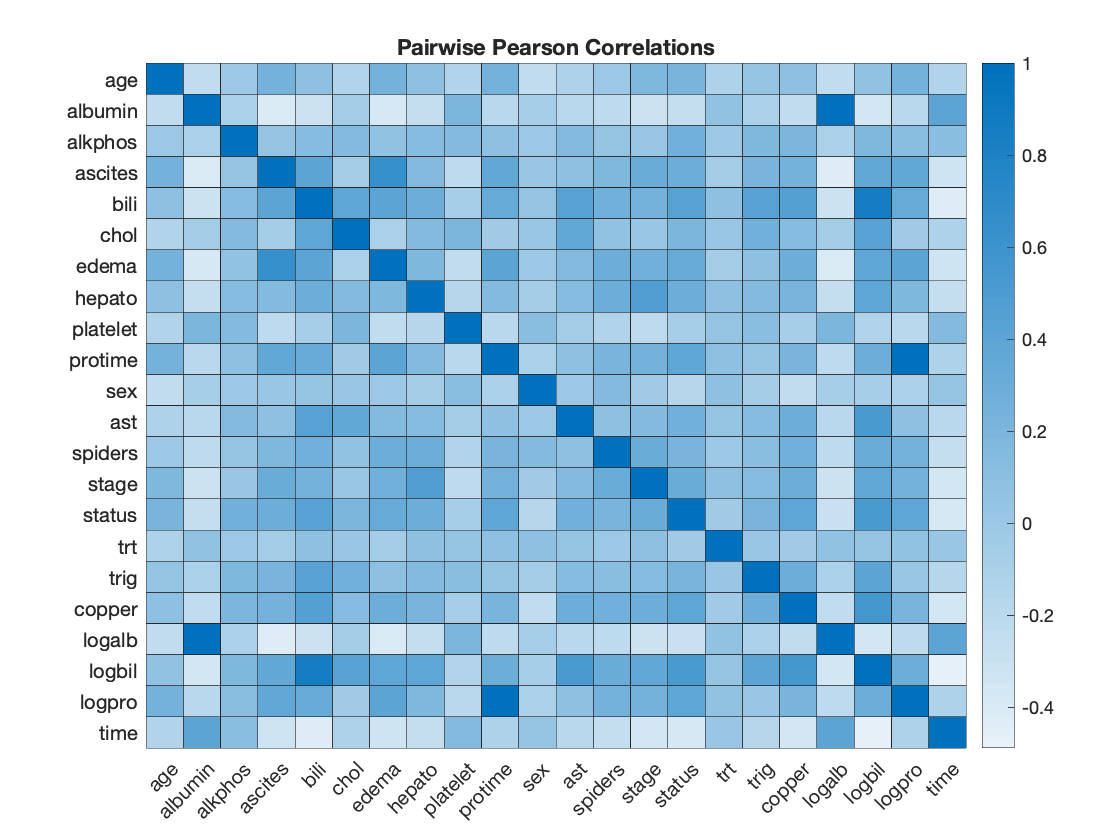

figure();
[R_pear,P_pear] = corr(table2array(cirrhosis),'Type','Pearson','rows','complete');
r_pear_map = heatmap(R_pear);
title('Pairwise Pearson Correlations')
r_pear_map.XDisplayLabels = cirrhosis_names;
r_pear_map.YDisplayLabels = cirrhosis_names;

% Features sorted by Correlation
absR_pear_time = abs(R_pear(1:end-1,end));
[absR_pear_time,I] = sort(absR_pear_time,'descend');
P_rank_time = P_pear(1:end-1,end);
cirrhosis_names_table = cirrhosis_names(1:end-1);
cirrhosis_names_table = cirrhosis_names_table(I);
pearsonTable = table(cirrhosis_names_table',absR_pear_time,P_rank_time(I),...
    'VariableNames',{'Feature','Correlation','pValue'})

pearsonTable = 21×3 table
      Feature       Correlation      pValue  
    ____________    ___________    __________

    {'logbil'  }      0.48822      6.1492e-18
    {'bili'    }      0.43025      7.2831e-14
    {'logalb'  }      0.40255      3.5578e-12
    {'albumin' }      0.40188      3.8929e-12
    {'status'  }      0.38453      3.7074e-11
    {'stage'   }      0.36388      4.5828e-10
    {'copper'  }      0.36139      6.1358e-10
    {'edema'   }      0.34711      3.1082e-09
    {'ascites' }      0.32945      2.0746e-08
    {'hepato'  }      0.26102      1.1172e-05
    {'spiders' }       0.2606      1.1553e-05
    {'ast'     }      0.19106       0.0014268
    {'trig'    }      0.16385       0.0063675
    {'platelet'}      0.15912       0.0080869
    {'age'     }      0.14322        0.017271
    {'chol'    }      0.13673        0.023088


### Pairwise pearson correlations with log time

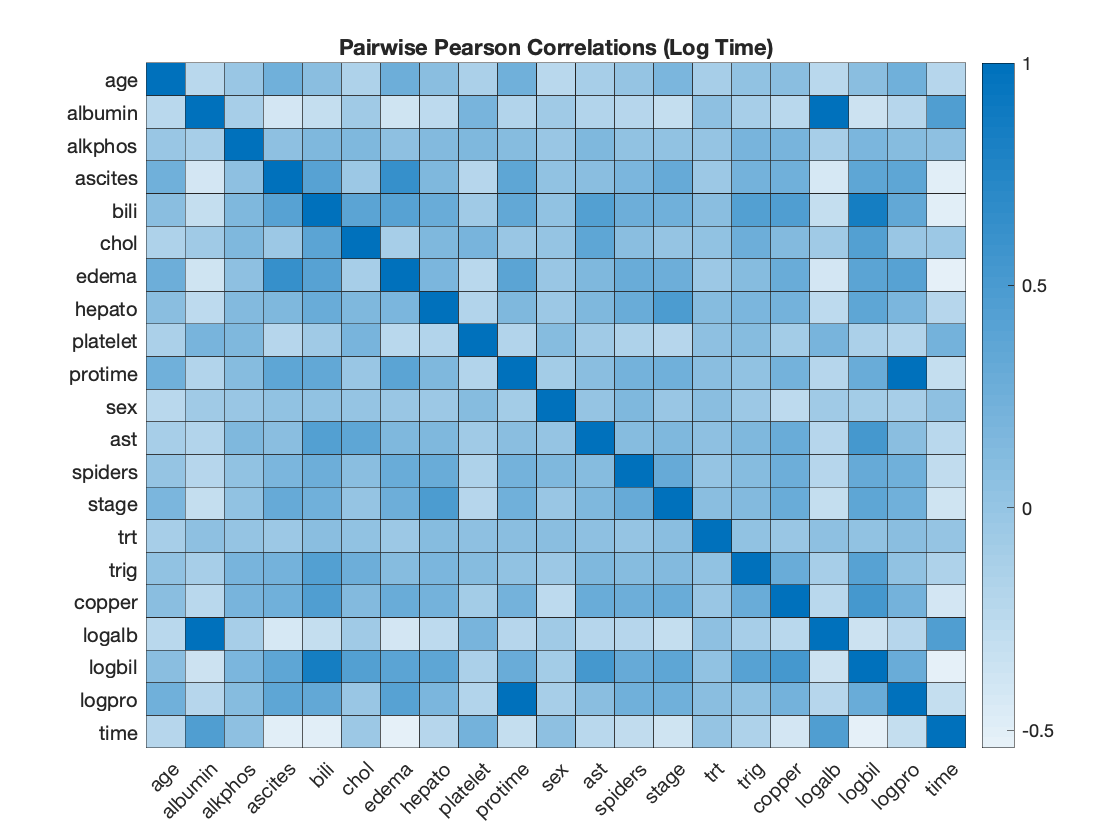

figure();
[R_pear_log,P_pear_log] = corr(table2array(cirrhosis_log),'Type','Pearson','rows','complete');
r_pear_log_map = heatmap(R_pear_log);
title('Pairwise Pearson Correlations (Log Time)')
r_pear_log_map.XDisplayLabels = cirrhosis_log_names;
r_pear_log_map.YDisplayLabels = cirrhosis_log_names;

absR_pear_log_time = abs(R_pear_log(1:end-1,end));
[absR_pear_log_time,I] = sort(absR_pear_log_time,'descend');
P_rank_time = P_pear_log(1:end-1,end);
cirrhosis_names_table = cirrhosis_log_names(1:end-1);
cirrhosis_names_table = cirrhosis_names_table(I);
pearsonLogTable = table(cirrhosis_names_table',absR_pear_log_time,P_rank_time(I),...
    'VariableNames',{'Feature','Correlation','pValue'})

pearsonLogTable = 20×3 table
      Feature       Correlation      pValue  
    ____________    ___________    __________

    {'edema'   }      0.54023      2.5921e-22
    {'logbil'  }      0.52419      6.9829e-21
    {'ascites' }      0.51327       5.959e-20
    {'bili'    }       0.5025      4.5844e-19
    {'logalb'  }      0.45997      7.4188e-16
    {'albumin' }      0.44713      5.6923e-15
    {'copper'  }      0.40194      3.8594e-12
    {'stage'   }      0.38146      5.4442e-11
    {'logpro'  }      0.31642      7.8083e-08
    {'protime' }      0.31497      9.0153e-08
    {'spiders' }      0.29343      6.9635e-07
    {'ast'     }       0.2402      5.5398e-05
    {'platelet'}      0.22785      0.00013423
    {'hepato'  }      0.22213      0.00019906
    {'age'     }      0.22042      0.00022361
    {'trig'    }      0.16421       0.0062528


## Task 4 - Unsupervised Learning 

We did PCA and K-means clustering. We evaluated how the data groups with respect to the dependent categorical variable **status**.

### PCA

% Remove status and try to find pca that detemines best features to predict status
cirrhosis_status_rm = cirrhosis_status;
cirrhosis_status_rm.status = [];
[coef, score, ~, ~, explained] = pca(zscore(table2array(cirrhosis_status_rm)));
% [coef, score, ~, ~, explained] = pca(table2array(cirrhosis_status_rm));  %Use this instead if you are working zscore data
% %Variance explained by PC1 and PC2 
explained(1:2)

ans =    26.0297
   11.6807


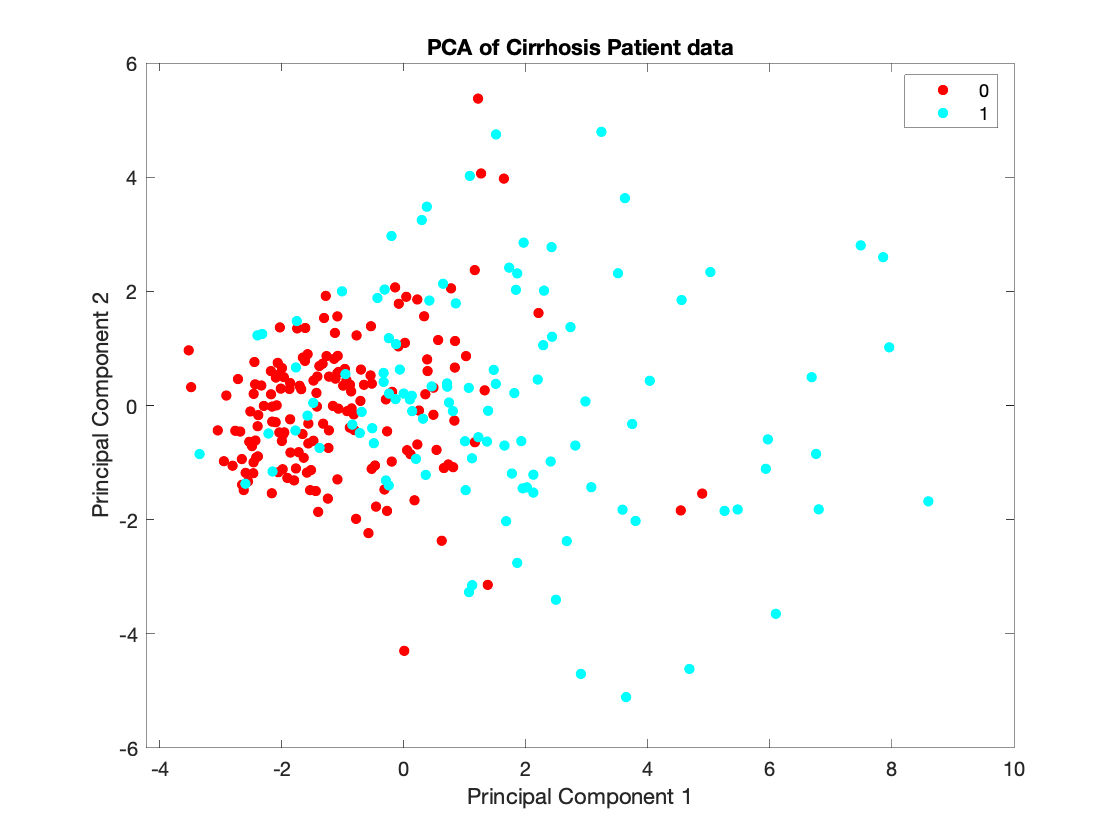

% Plot PCA and color by status
figure();
gscatter(score(:,1), score(:,2), cirrhosis_status.status)
xlabel('Principal Component 1')
ylabel('Principal Component 2')
title('PCA of Cirrhosis Patient data')

PC1_coeff = coef(:,1);
PC2_coeff = coef(:,2);
% Table of PCA Coefficients
T = table(cirrhosis_status_rm.Properties.VariableNames', PC1_coeff, PC2_coeff)

T = 20×3 table
        Var1        PC1_coeff    PC2_coeff 
    ____________    _________    __________

    {'age'     }      0.12559       -0.2995
    {'albumin' }     -0.28558       0.10063
    {'alkphos' }     0.090047       0.17586
    {'ascites' }      0.27877      -0.18012
    {'bili'    }      0.32976       0.25299
    {'chol'    }     0.096294       0.45334
    {'edema'   }      0.28652      -0.20801
    {'hepato'  }      0.21158        0.0657
    {'platelet'}      -0.1308       0.25531
    {'protime' }      0.25442      -0.26757
    {'sex'     }     -0.03293      0.052072
    {'ast'     }      0.18022       0.31766
    {'spiders' }      0.19866    -0.0038888
    {'stage'   }      0.23995     -0.066253
    {'trt'     }    0.0059991       0.07292
    {'trig'    }      0.15791       0.29339


% Table of PCA sorted by PC1
T_PC1 = sortrows(T,'PC1_coeff','descend')

T_PC1 = 20×3 table
       Var1        PC1_coeff    PC2_coeff 
    ___________    _________    __________

    {'logbil' }      0.34594       0.27972
    {'bili'   }      0.32976       0.25299
    {'edema'  }      0.28652      -0.20801
    {'ascites'}      0.27877      -0.18012
    {'logpro' }      0.25887      -0.26773
    {'protime'}      0.25442      -0.26757
    {'copper' }      0.25314       0.15034
    {'stage'  }      0.23995     -0.066253
    {'hepato' }      0.21158        0.0657
    {'spiders'}      0.19866    -0.0038888
    {'ast'    }      0.18022       0.31766
    {'trig'   }      0.15791       0.29339
    {'age'    }      0.12559       -0.2995
    {'chol'   }     0.096294       0.45334
    {'alkphos'}     0.090047       0.17586
    {'trt'    }    0.0059991       0.07292


% Table of PCA sorted by PC2
T_PC2 = sortrows(T,'PC2_coeff','descend')

T_PC2 = 20×3 table
        Var1        PC1_coeff    PC2_coeff 
    ____________    _________    __________

    {'chol'    }     0.096294       0.45334
    {'ast'     }      0.18022       0.31766
    {'trig'    }      0.15791       0.29339
    {'logbil'  }      0.34594       0.27972
    {'platelet'}      -0.1308       0.25531
    {'bili'    }      0.32976       0.25299
    {'alkphos' }     0.090047       0.17586
    {'copper'  }      0.25314       0.15034
    {'logalb'  }     -0.28947       0.10475
    {'albumin' }     -0.28558       0.10063
    {'trt'     }    0.0059991       0.07292
    {'hepato'  }      0.21158        0.0657
    {'sex'     }     -0.03293      0.052072
    {'spiders' }      0.19866    -0.0038888
    {'stage'   }      0.23995     -0.066253
    {'ascites' }      0.27877      -0.18012


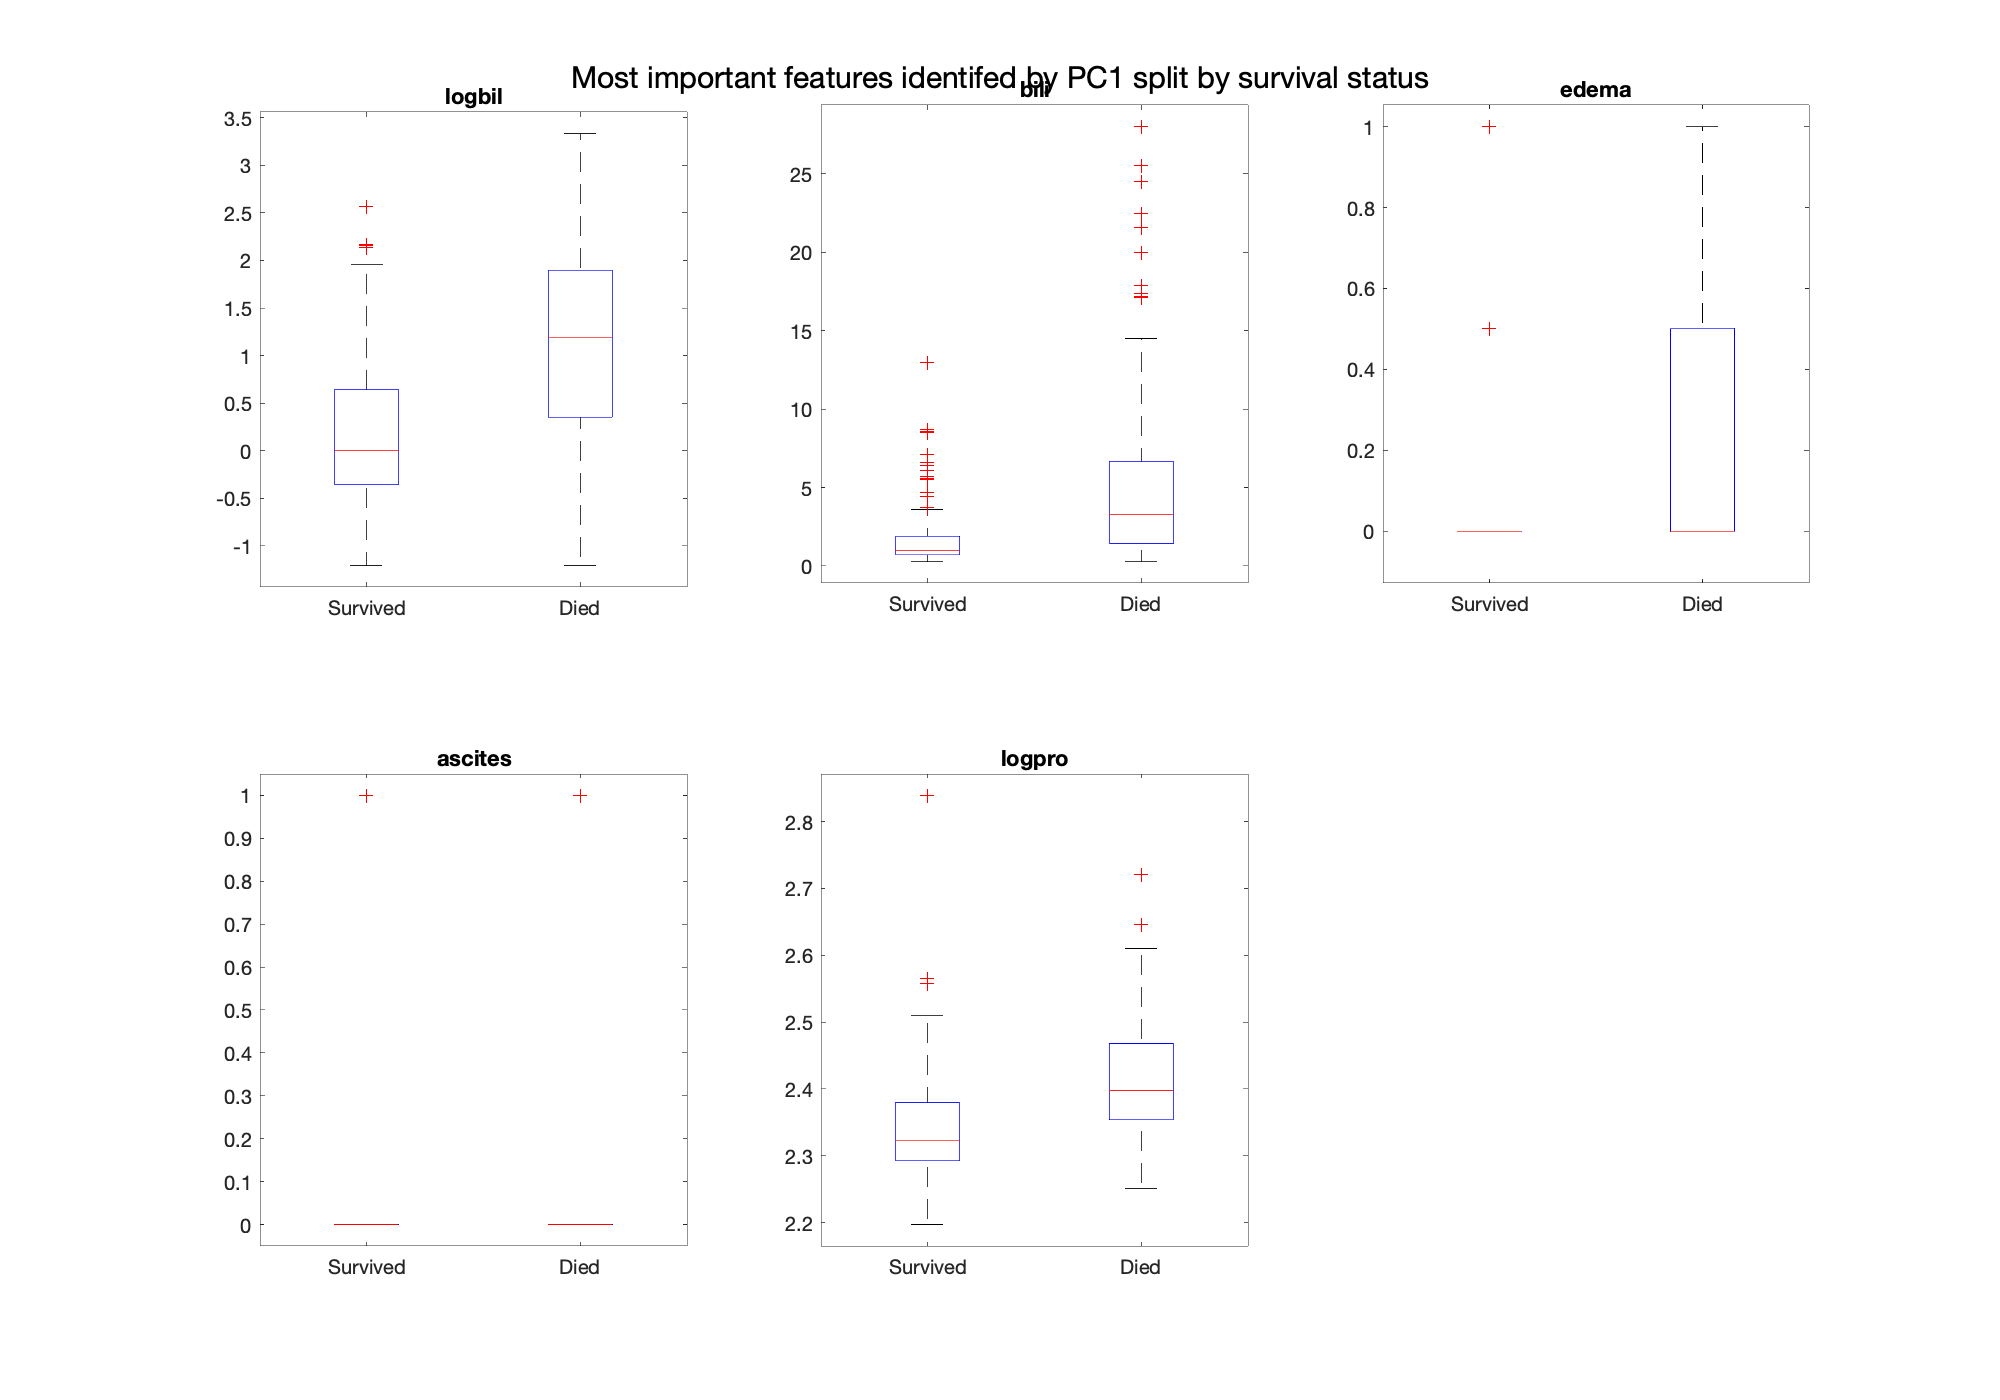

%Box plots exploring top 5 features recognized as having most weight from from PC1
%Features split on status
f = figure();
set(f, 'Position', expandFigSize)
sgtitle('Most important features identifed by PC1 split by survival status')
features = T_PC1.Var1(1:5);
features_analyzed = cell(5,2);
features_analyzed(:,1) = features;
for i=1:length(features)
    subplot(2,3,i)
    boxplot(cirrhosis_status.(features{i}),cirrhosis_status.status, 'Labels',{'Survived','Died'})
    title(features{i})
    [h,p] = ttest2(cirrhosis_status.(features{i})(cirrhosis_status.status == 0),cirrhosis_status.(features{i})(cirrhosis_status.status == 1));
    features_analyzed{i,2} = p;
end

T_PC1_analyzed = cell2table(features_analyzed);
T_PC1_analyzed.Properties.VariableNames = {'Features','P values'}

T_PC1_analyzed = 5×2 table
     Features       P values 
    ___________    __________

    {'logbil' }    7.4316e-18
    {'bili'   }    3.5816e-13
    {'edema'  }    1.5362e-08
    {'ascites'}    3.0548e-07
    {'logpro' }    3.8126e-12


### K-Means Clustering

figure();
kValues = 2:10;
n       = length(kValues);
s_score = zeros(n,1);

for i = 1:n
    idx = kmeans(table2array(cirrhosis_status),kValues(i)); % k-means clustering
    s = silhouette(table2array(cirrhosis_status),idx);      % silhouette values
    s_score(i) = mean(s);                                % silhouette score
end
table(kValues',s_score)

ans = 9×2 table
    Var1    s_score
    ____    _______

      2     0.92736
      3     0.88104
      4     0.74122
      5     0.72355
      6     0.68459
      7     0.64776
      8     0.64287
      9     0.57722
     10     0.59783


k = find(s_score==max(s_score))+1 % k = 2 is best

k = 2

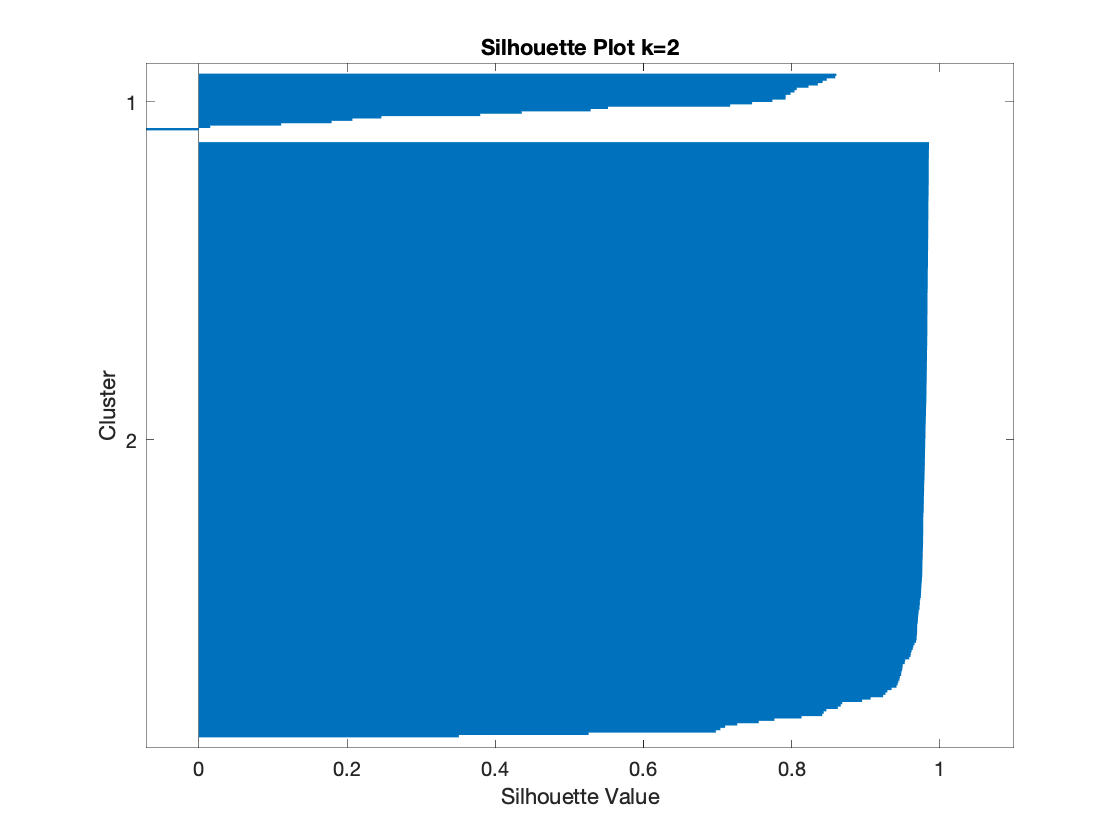

% Plot silhouette for optimal cluster size
idx = kmeans(table2array(cirrhosis_status),k);
silhouette(table2array(cirrhosis_status),idx)
title('Silhouette Plot k=2')

%Predicting status for each cluster from k-means
cluster1 = (cirrhosis_status.status(idx == 1));
cluster1_survived = sum((cluster1 == 0))

cluster1_survived = 7

cluster1_died = sum((cluster1 == 1))

cluster1_died = 17


cluster2 = (cirrhosis_status.status(idx == 2));
cluster2_survived = sum((cluster2 == 0))

cluster2_survived = 158

cluster2_died = sum((cluster2 == 1))

cluster2_died = 94

### Task 5 - Supervised Learning on Time

### Linear regression using all the data and nonlog values of time

b_lin = fitlm(cirrhosis)

b_lin = Linear regression model:
    time ~ 1 + age + albumin + alkphos + ascites + bili + chol + edema + hepato + platelet + protime + sex + ast + spiders + stage + status + trt + trig + copper + logalb + logbil + logpro

Estimated Coefficients:
                   Estimate        SE         tStat         pValue  
                   _________    ________    __________    __________

    (Intercept)       -26619       10653       -2.4988      0.013093
    age               1.4508      5.8132       0.24956       0.80313
    albumin           1083.3      1282.2       0.84487       0.39898
    alkphos          0.11516    0.027248        4.2264    3.3141e-05
    ascites          -180.94      296.96       -0.6093       0.54287
    bili             -24.179   

% Show the significant coefficients
b_lin.Coefficients(b_lin.Coefficients.pValue < 0.05,:)

ans = 6×4 table
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     -26619        10653    -2.4988      0.013093
    alkphos        0.11516     0.027248     4.2264    3.3141e-05
    protime        -1366.2       631.37    -2.1638      0.031411
    stage          -183.65       79.029    -2.3238      0.020924
    status         -264.43       72.511    -3.6468    0.00032215
    logpro           17841       7293.8     2.4461       0.01512


### Lasso, Stepwise, and Linear Regression

Used cirrhosis_log because we used log time for all regression models

% Top 10 features for linear regression
[B,I] = maxk(abs(R_pear_log(end,1:end-1)),10);
linear_reg_names = [{'(Intercept)'},cirrhosis_log_names(I)];
% Generate crossvalidation groups
NFolds  = 5;
indices = crossvalind('kfold',size(cirrhosis_log,1),NFolds);
% Declare datasets for storing the outputs
regressionModel = struct();
subsets = {subset, subset_log};
% Run the analysis
for i=1:NFolds
    test = (indices == i);   
    train = ~test;   
    % Extract train rows from X and Y
    trainData = cirrhosis_log(train,:);
    Xtrain = table2array(trainData(:,1:end-1));
    Ytrain = table2array(trainData(:,end));
    % Extract test rows from X and Y
    testData = cirrhosis_log(test,:);
    Xtest = table2array(testData(:,1:end-1));
    Ytest = table2array(testData(:,end));
    
    % Lasso
    % Make model and predict
    [lassoB,lassoFit] = lasso(Xtrain,Ytrain,'CV',NFolds);
    coef0 = lassoFit.Intercept(lassoFit.IndexMinMSE);
    coef  = lassoB(:,lassoFit.IndexMinMSE);
    Ypred = Xtest*coef + coef0;
    % Get best coef
    ncoef = sum(coef ~= 0);
    [~,maxCoefIdx] = maxk(abs(coef),ncoef);
    % Save fit for later and evaluate the model
    regressionModel.lasso.fit{i} = lassoFit;
    regressionModel.lasso.coeffVals{i} = coef(maxCoefIdx);
    regressionModel.lasso.coeffNames{i} = cirrhosis_names(maxCoefIdx)';
    regressionModel.lasso.ncoef(i) = ncoef;
    regressionModel.lasso.absError(i) = mean(abs(Ypred-Ytest));
    [regressionModel.lasso.corrR(i),regressionModel.lasso.corrP(i)] = corr(Ytest,Ypred);
    [regressionModel.lasso.rankCorrR(i),regressionModel.lasso.rankCorrP(i)] = corr(Ytest,Ypred,'Type','Spearman');
    
    % Stepwise fit
    for j=1:3
        if j == 1
            stepFit = stepwiselm(trainData,'Upper','linear','ResponseVar','time','CategoricalVars',categVar,'Verbose',0);
        else
            stepFit = stepwiselm(trainData,'Upper','linear','ResponseVar','time','PredictorVars',subsets{j-1},'Verbose',0);
        end
        Ypred = stepFit.predict(Xtest);
        
         [~,coefIdx] = sort(stepFit.Coefficients.pValue);
        
        % Save fit for later and evaluate the model
        regressionModel.step(j).fit{i} = stepFit;
        regressionModel.step(j).coeffNames{i}  = stepFit.Coefficients.Row(coefIdx);
        regressionModel.step(j).coeffVals{i}   = stepFit.Coefficients.Estimate(coefIdx);
        regressionModel.step(j).ncoef(i)       = stepFit.NumPredictors;
        regressionModel.step(j).rSquared(i)    = stepFit.Rsquared.Ordinary;
        regressionModel.step(j).rSquaredAdj(i) = stepFit.Rsquared.Adjusted;
        regressionModel.step(j).absError(i)    = mean(abs(Ypred-Ytest));
        [regressionModel.step(j).corrR(i),regressionModel.step(j).corrP(i)] = corr(Ytest,Ypred);
        [regressionModel.step(j).rankCorrR(i),regressionModel.step(j).rankCorrP(i)] = corr(Ytest,Ypred,'Type','Spearman');
    end
   
    % Linear
    % Make model and predict
    mdl = fitlm(Xtrain(:,I),Ytrain);
    Ypred = mdl.predict(Xtest(:,I));
    
    [~,coefIdx] = sort(mdl.Coefficients.pValue);
    % Evaluate the model
    regressionModel.linear.fit{i} = mdl;
    regressionModel.linear.features{i}    = linear_reg_names;
    regressionModel.linear.coeffNames{i}  = linear_reg_names(coefIdx)';
    regressionModel.linear.coeffVals{i}   = mdl.Coefficients.Estimate(coefIdx);
    regressionModel.linear.rSquared(i)    = mdl.Rsquared.Ordinary;
    regressionModel.linear.rSquaredAdj(i) = mdl.Rsquared.Adjusted;
    regressionModel.linear.ncoef(i)       = length(B);
    regressionModel.linear.absError(i)    = mean(abs(Ypred-Ytest));
    [regressionModel.linear.corrR(i),regressionModel.linear.corrP(i)] = corr(Ytest,Ypred);
    [regressionModel.linear.rankCorrR(i),regressionModel.linear.rankCorrP(i)] = corr(Ytest,Ypred,'Type','Spearman');
end

### Lasso Analysis

rowNames = cellfun(@(s)sprintf('Subsample %d',s),num2cell(transpose(1:NFolds)),'UniformOutput',false);
varNames = ["ncoeff","Average Absolute Error","Pearsons Correlation",...
    "Pearsons Correlation P-val","Rank Correlation", "Rank Correlation P-val"];
table(regressionModel.lasso.ncoef',regressionModel.lasso.absError',regressionModel.lasso.corrR',...
    regressionModel.lasso.corrP',regressionModel.lasso.rankCorrR',regressionModel.lasso.rankCorrP',...
    'VariableNames', varNames,'RowNames', rowNames)

ans = 5×6 table
                   ncoeff    Average Absolute Error    Pearsons Correlation    Pearsons Correlation P-val    Rank Correlation    Rank Correlation P-val
                   ______    ______________________    ____________________    __________________________    ________________    ______________________

    Subsample 1       9             0.44316                  0.70356                   1.4711e-09                0.53473               2.1819e-05      
    Subsample 2       8             0.53501                  0.74668                   5.9488e-11                0.63687                3.735e-07      
    Subsample 3      10             0.39866                  0.68561                   7.6779e-09                0.60072

maxRow = max(regressionModel.lasso.ncoef);
T = table();
for i=1:NFolds
    tempT = table([regressionModel.lasso.coeffNames{i},num2cell(regressionModel.lasso.coeffVals{i})],...
        'VariableNames',cellstr(sprintf("Subset %i",i)));
    T2Pad = [tempT;repmat({[{NaN},{NaN}]},maxRow-size(tempT,1),1)];
    T = [T T2Pad];
end
T

T = 16×5 table
               Subset 1                          Subset 2                          Subset 3                          Subset 4                           Subset 5            
    ______________________________    ______________________________    ______________________________    _______________________________    _______________________________

    {'copper' }    {[     1.0398]}    {'edema'  }    {[    -0.8454]}    {'copper' }    {[     0.8147]}    {'copper'  }    {[     1.2322]}    {'copper'  }    {[     0.8193]}
    {'ascites'}    {[    -0.5812]}    {'copper' }    {[     0.5156]}    {'edema'  }    {[    -0.6898]}    {'ascites' }    {[    -0.4140]}    {'edema'   }    {[    -0.5482]}
    {'edema'  }    {[    -0.4742]}    {'ascites'}    {[    -0.4198]}    {'ascites'}    {[    -0.5355]}    {'edema'   }    

### Linear Analysis

linVarNames = ["R-Squared","Adjusted R-Squared","ncoeff","Average Absolute Error","Pearsons Correlation",...
    "Pearsons Correlation P-val","Rank Correlation", "Rank Correlation P-val"];
table(regressionModel.linear.rSquared',regressionModel.linear.rSquaredAdj',regressionModel.linear.ncoef',...
    regressionModel.linear.absError',regressionModel.linear.corrR',regressionModel.linear.corrP',...
    regressionModel.linear.rankCorrR',regressionModel.linear.rankCorrP',...
    'VariableNames', linVarNames,'RowNames', rowNames)

ans = 5×8 table
                   R-Squared    Adjusted R-Squared    ncoeff    Average Absolute Error    Pearsons Correlation    Pearsons Correlation P-val    Rank Correlation    Rank Correlation P-val
                   _________    __________________    ______    ______________________    ____________________    __________________________    ________________    ______________________

    Subsample 1     0.49578          0.47166            10              0.4621                  0.70107                   1.7786e-09                0.52298               3.5474e-05      
    Subsample 2     0.45162           0.4255            10             0.52655                  0.74826             

maxRow = max(regressionModel.linear.ncoef);
T = table();
for i=1:NFolds
    tempT = table([regressionModel.linear.coeffNames{i},num2cell(regressionModel.linear.coeffVals{i})],...
        'VariableNames',cellstr(sprintf("Subset %i",i)));
    T2Pad = [tempT;repmat({[{NaN},{NaN}]},maxRow-size(tempT,1),1)];
    T = [T T2Pad];
end
T

T = 11×5 table
                 Subset 1                              Subset 2                              Subset 3                            Subset 4                          Subset 5           
    __________________________________    __________________________________    __________________________________    ______________________________    ______________________________

    {'stage'      }    {[    -0.1503]}    {'edema'      }    {[    -0.9025]}    {'edema'      }    {[    -0.7777]}    {'copper'     }    {[-0.0014]}    {'edema'      }    {[-0.6937]}
    {'ascites'    }    {[    -0.5725]}    {'stage'      }    {[    -0.1236]}    {'logpro'     }    {[    18.0918]}    {'stage'      }    {[-0.1230]}    {'copper'     }    {[-0.0011]}
    {'edema'      }    {[    -0.4901]}    {'ascites'    }    {[    -0.4427]}    {'

### Stepwise Analysis

stepVarNames = ["R-Squared","Adjusted R-Squared","Number of Predictors","Average Absolute Error","Pearsons Correlation",...
    "Pearsons Correlation P-val","Rank Correlation", "Rank Correlation P-val"];
stepTables = cell(3,1);
for i=1:3
    stepTables{i} = table(regressionModel.step(i).rSquared',regressionModel.step(i).rSquaredAdj',...
        regressionModel.step(i).ncoef',regressionModel.step(i).absError',regressionModel.step(i).corrR',...
        regressionModel.step(i).corrP',regressionModel.step(i).rankCorrR',regressionModel.step(i).rankCorrP',...
        'VariableNames', stepVarNames,'RowNames', rowNames);
end

#### Stepwise Full

j = 1;
stepTables{j}

ans = 5×8 table
                   R-Squared    Adjusted R-Squared    Number of Predictors    Average Absolute Error    Pearsons Correlation    Pearsons Correlation P-val    Rank Correlation    Rank Correlation P-val
                   _________    __________________    ____________________    ______________________    ____________________    __________________________    ________________    ______________________

    Subsample 1     0.49536          0.47869                   6                     0.43348                  0.72495                   2.6534e-10                0.57147               4.2235e-06      
    Subsample 2     0.44808          0.43524                   4          

maxRow = max(cellfun('length',regressionModel.step(j).coeffNames));
T = table();
for i=1:NFolds
    tempT = table([regressionModel.step(j).coeffNames{i},num2cell(regressionModel.step(j).coeffVals{i})],...
        'VariableNames',cellstr(sprintf("Subset %i",i)));
    T2Pad = [tempT;repmat({[{NaN},{NaN}]},maxRow-size(tempT,1),1)];
    T = [T T2Pad];
end
T

T = 9×5 table
                Subset 1                             Subset 2                             Subset 3                             Subset 4                             Subset 5             
    _________________________________    _________________________________    _________________________________    _________________________________    _________________________________

    {'(Intercept)'}    {[    5.8974]}    {'(Intercept)'}    {[    6.3724]}    {'(Intercept)'}    {[    6.2523]}    {'(Intercept)'}    {[    6.3346]}    {'(Intercept)'}    {[    5.7779]}
    {'logbil'     }    {[   -0.2326]}    {'edema_1'    }    {[   -1.3755]}    {'logbil'     }    {[   -0.2044]}    {'logbil'     }    {[   -0.2195]}    {'logbil'     }    {[   -0.2953]}
    {'alkphos'    }    {[5.9631e-05]}    {'logbil'     }    {[   -0.236

#### Stepwise Subset

j = 2;
stepTables{j}

ans = 5×8 table
                   R-Squared    Adjusted R-Squared    Number of Predictors    Average Absolute Error    Pearsons Correlation    Pearsons Correlation P-val    Rank Correlation    Rank Correlation P-val
                   _________    __________________    ____________________    ______________________    ____________________    __________________________    ________________    ______________________

    Subsample 1     0.46076          0.44557                   6                     0.41958                  0.70178                   1.6852e-09                0.57561               3.4669e-06      
    Subsample 2     0.42368          0.41027                   5          

maxRow = max(cellfun('length',regressionModel.step(j).coeffNames));
T = table();
for i=1:NFolds
    tempT = table([regressionModel.step(j).coeffNames{i},num2cell(regressionModel.step(j).coeffVals{i})],...
        'VariableNames',cellstr(sprintf("Subset %i",i)));
    T2Pad = [tempT;repmat({[{NaN},{NaN}]},maxRow-size(tempT,1),1)];
    T = [T T2Pad];
end
T

T = 7×5 table
                Subset 1                             Subset 2                             Subset 3                             Subset 4                             Subset 5             
    _________________________________    _________________________________    _________________________________    _________________________________    _________________________________

    {'(Intercept)'}    {[    5.9967]}    {'(Intercept)'}    {[    6.5704]}    {'(Intercept)'}    {[    6.2191]}    {'(Intercept)'}    {[    5.7191]}    {'(Intercept)'}    {[    5.3539]}
    {'bili'       }    {[   -0.0477]}    {'edema'      }    {[   -0.9239]}    {'bili'       }    {[   -0.0486]}    {'bili'       }    {[   -0.0639]}    {'bili'       }    {[   -0.0787]}
    {'albumin'    }    {[    0.4463]}    {'bili'       }    {[   -0.040

#### Stepwise Subset Log

j = 3;
stepTables{j}

ans = 5×8 table
                   R-Squared    Adjusted R-Squared    Number of Predictors    Average Absolute Error    Pearsons Correlation    Pearsons Correlation P-val    Rank Correlation    Rank Correlation P-val
                   _________    __________________    ____________________    ______________________    ____________________    __________________________    ________________    ______________________

    Subsample 1     0.48501          0.47298                   5                     0.43333                  0.70188                   1.6733e-09                 0.5294                2.726e-05      
    Subsample 2     0.45217          0.43943                   5          

maxRow = max(cellfun('length',regressionModel.step(j).coeffNames));
T = table();
for i=1:NFolds
    tempT = table([regressionModel.step(j).coeffNames{i},num2cell(regressionModel.step(j).coeffVals{i})],...
        'VariableNames',cellstr(sprintf("Subset %i",i)));
    T2Pad = [tempT;repmat({[{NaN},{NaN}]},maxRow-size(tempT,1),1)];
    T = [T T2Pad];
end
T

T = 7×5 table
                Subset 1                             Subset 2                             Subset 3                             Subset 4                             Subset 5             
    _________________________________    _________________________________    _________________________________    _________________________________    _________________________________

    {'(Intercept)'}    {[    5.7683]}    {'(Intercept)'}    {[    6.5915]}    {'(Intercept)'}    {[    6.1085]}    {'(Intercept)'}    {[    5.6419]}    {'(Intercept)'}    {[    5.3857]}
    {'logbil'     }    {[   -0.2823]}    {'logbil'     }    {[   -0.2273]}    {'logbil'     }    {[   -0.2484]}    {'logbil'     }    {[   -0.2781]}    {'logbil'     }    {[   -0.3488]}
    {'logalb'     }    {[    1.3844]}    {'edema'      }    {[   -0.909

### Overall Averages Analysis

overSum = struct();
for i=1:3
    overSum.step(1,i) = mean(regressionModel.step(i).corrR);
    overSum.step(2,i) = mean(regressionModel.step(i).rankCorrR);
    overSum.step(3,i) = mean(regressionModel.step(i).absError);
    overSum.step(4,i) = mean(regressionModel.step(i).ncoef);
end
overSum.linear = [mean(regressionModel.linear.corrR)
    mean(regressionModel.linear.rankCorrR)
    mean(regressionModel.linear.absError)
    mean(regressionModel.linear.ncoef)];

overSum.lasso = [mean(regressionModel.lasso.corrR)
    mean(regressionModel.lasso.rankCorrR)
    mean(regressionModel.lasso.absError)
    mean(regressionModel.lasso.ncoef)];

sumVarNames = ["Stepwise Full", "Stepwise Subset", "Stepwise Subset Log", "Linear FitLm", "Lasso"];
sumRowNames = ["Pearsons Correlation","Rank Correlation","Mean Absolute Error","Number of Coefficients"];
table(overSum.step(:,1),overSum.step(:,2),overSum.step(:,3),overSum.linear,overSum.lasso,...
        'VariableNames', sumVarNames,'RowNames', sumRowNames)

ans = 4×5 table
                              Stepwise Full    Stepwise Subset    Stepwise Subset Log    Linear FitLm     Lasso 
                              _____________    _______________    ___________________    ____________    _______

    Pearsons Correlation          0.6467           0.61701              0.65881             0.6305       0.64704
    Rank Correlation             0.56324           0.55785              0.56266            0.52592       0.55494
    Mean Absolute Error          0.46382           0.48355              0.46373            0.47439       0.46848
    Number of Coefficients             6                 5                  5.2                 10          11.4


### Method Comparision Plots

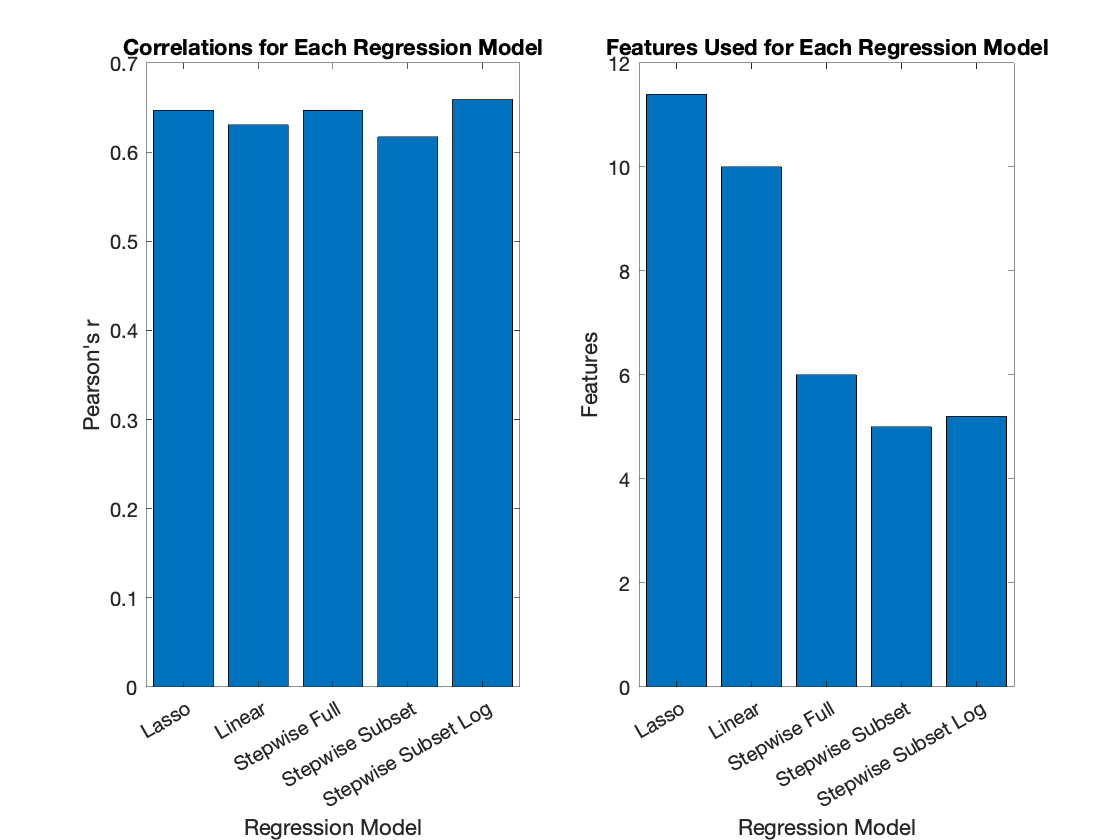

figure();
subplot(1,2,1)
X = categorical({'Lasso','Stepwise Full','Stepwise Subset','Stepwise Subset Log','Linear'});
bar(X,[overSum.lasso(1),overSum.step(1,:),overSum.linear(1)])
title('Correlations for Each Regression Model')
xlabel('Regression Model')
ylabel("Pearson's r")
subplot(1,2,2)
bar(X,[overSum.lasso(4),overSum.step(4,:),overSum.linear(4)])
title('Features Used for Each Regression Model')
xlabel('Regression Model')
ylabel("Features")

## Task 6 - Supervised Learning on Status

### Logistic Regression

% Number of features to select
NFeatures = 8;

cirrhosis_status_array = table2array(cirrhosis_status);

accuracyGuess = zeros(100,NFolds);
meanGuess = zeros(NFolds,1);
sigDiff = zeros(NFolds,2);

for i=1:NFolds
    test = (indices == i);
    train = ~test;
    
    % Extract train rows from X and Y
    Xtrain = cirrhosis_status_array(train,1:end-1);
    Ytrain = cirrhosis_status_array(train,end);
    
    % Extract test rows from X and Y
    Xtest = cirrhosis_status_array(test,1:end-1);
    Ytest = cirrhosis_status_array(test,end);
    
    % Create logistic model with train data.
    [b,dev,stats] = mnrfit(Xtrain, categorical(Ytrain)); 
    [p,I] = sort(stats.p(2:end,:));
    [p_min,min_idx] = min(p,[],2);
    regressionModel.logist.bestP{i} = p_min(1:NFeatures);
    regressionModel.logist.bestFeatures{i} = diag(I(1:NFeatures,min_idx(1:NFeatures)));
    regressionModel.logist.bestFeaturesNames{i} = cirrhosis_status_names(regressionModel.logist.bestFeatures{i})';
    regressionModel.logist.bestFeaturesCoeff{i} = b(I(1:NFeatures));
    
    % Predict Y values from model.
    Ypred = mnrval(b,Xtest);   
    [~,Ypred] = max(Ypred,[],2);
    Ypred = double(Ypred - 1);
    
    %Comparing model to 100 random guesses
    for k = 1:100
        random_pred = Ytrain(randperm(length(Ytest)));
        accuracyGuess(k,i) = sum(random_pred == Ytest)/length(Ytest);        
    end
    meanGuess(i) = mean(accuracyGuess(:,i));
    accuracy = sum(Ypred == Ytest)/length(Ypred);
    %T test comparing model accuracy to random guess accuracy
    [sigDiff(i,1),sigDiff(i,2)] = ttest2(accuracy,accuracyGuess(:,i));
    meanGuessError = meanGuess(i) - accuracy;
    
    % Evaluate Model
    regressionModel.logist.confusion{i} = confusionmat(Ytest,Ypred);
    regressionModel.logist.accuracy(i)  = accuracy;
    regressionModel.logist.precision(i) = sum(Ypred ~=0 & Ypred==Ytest)/sum(Ypred~=0);
    regressionModel.logist.recall(i)    = sum(Ypred ~=0 & Ytest ==Ypred)/sum(Ytest~=0);
    regressionModel.logist.absError(i)  = mean(abs(Ypred - Ytest));
    [regressionModel.logist.corrR(i),regressionModel.logist.corrP(i)] = corr(Ypred,Ytest);
    [regressionModel.logist.rankCorrR(i),regressionModel.logist.rankCorrP(i)] = corr(Ypred,Ytest,'Type','Spearman');
    regressionModel.logist.meanGuessError(i) = meanGuessError;
    regressionModel.logist.compareGuess(i)   = sigDiff(i,2);
end

### Logistic Regression Analysis

logVarNames = ["Accuracy","Precision","Recall","Average Absolute Error","Pearsons Correlation",...
    "Pearsons Correlation P-val","Rank Correlation", "Rank Correlation P-val","Mean Guess Error","Guess Difference"];
table(regressionModel.logist.accuracy',regressionModel.logist.precision',regressionModel.logist.recall',...
    regressionModel.logist.absError',regressionModel.logist.corrR',regressionModel.logist.corrP',...
    regressionModel.logist.rankCorrR',regressionModel.logist.rankCorrP', regressionModel.logist.meanGuessError',...
    regressionModel.logist.compareGuess','VariableNames',logVarNames,'RowNames', rowNames)

ans = 5×10 table
                   Accuracy    Precision    Recall     Average Absolute Error    Pearsons Correlation    Pearsons Correlation P-val    Rank Correlation    Rank Correlation P-val    Mean Guess Error    Guess Difference
                   ________    _________    _______    ______________________    ____________________    __________________________    ________________    ______________________    ________________    ________________

    Subsample 1    0.71429      0.68182       0.625           0.28571                  0.41165                    0.0016215                0.41165                0.0016215              -0.2

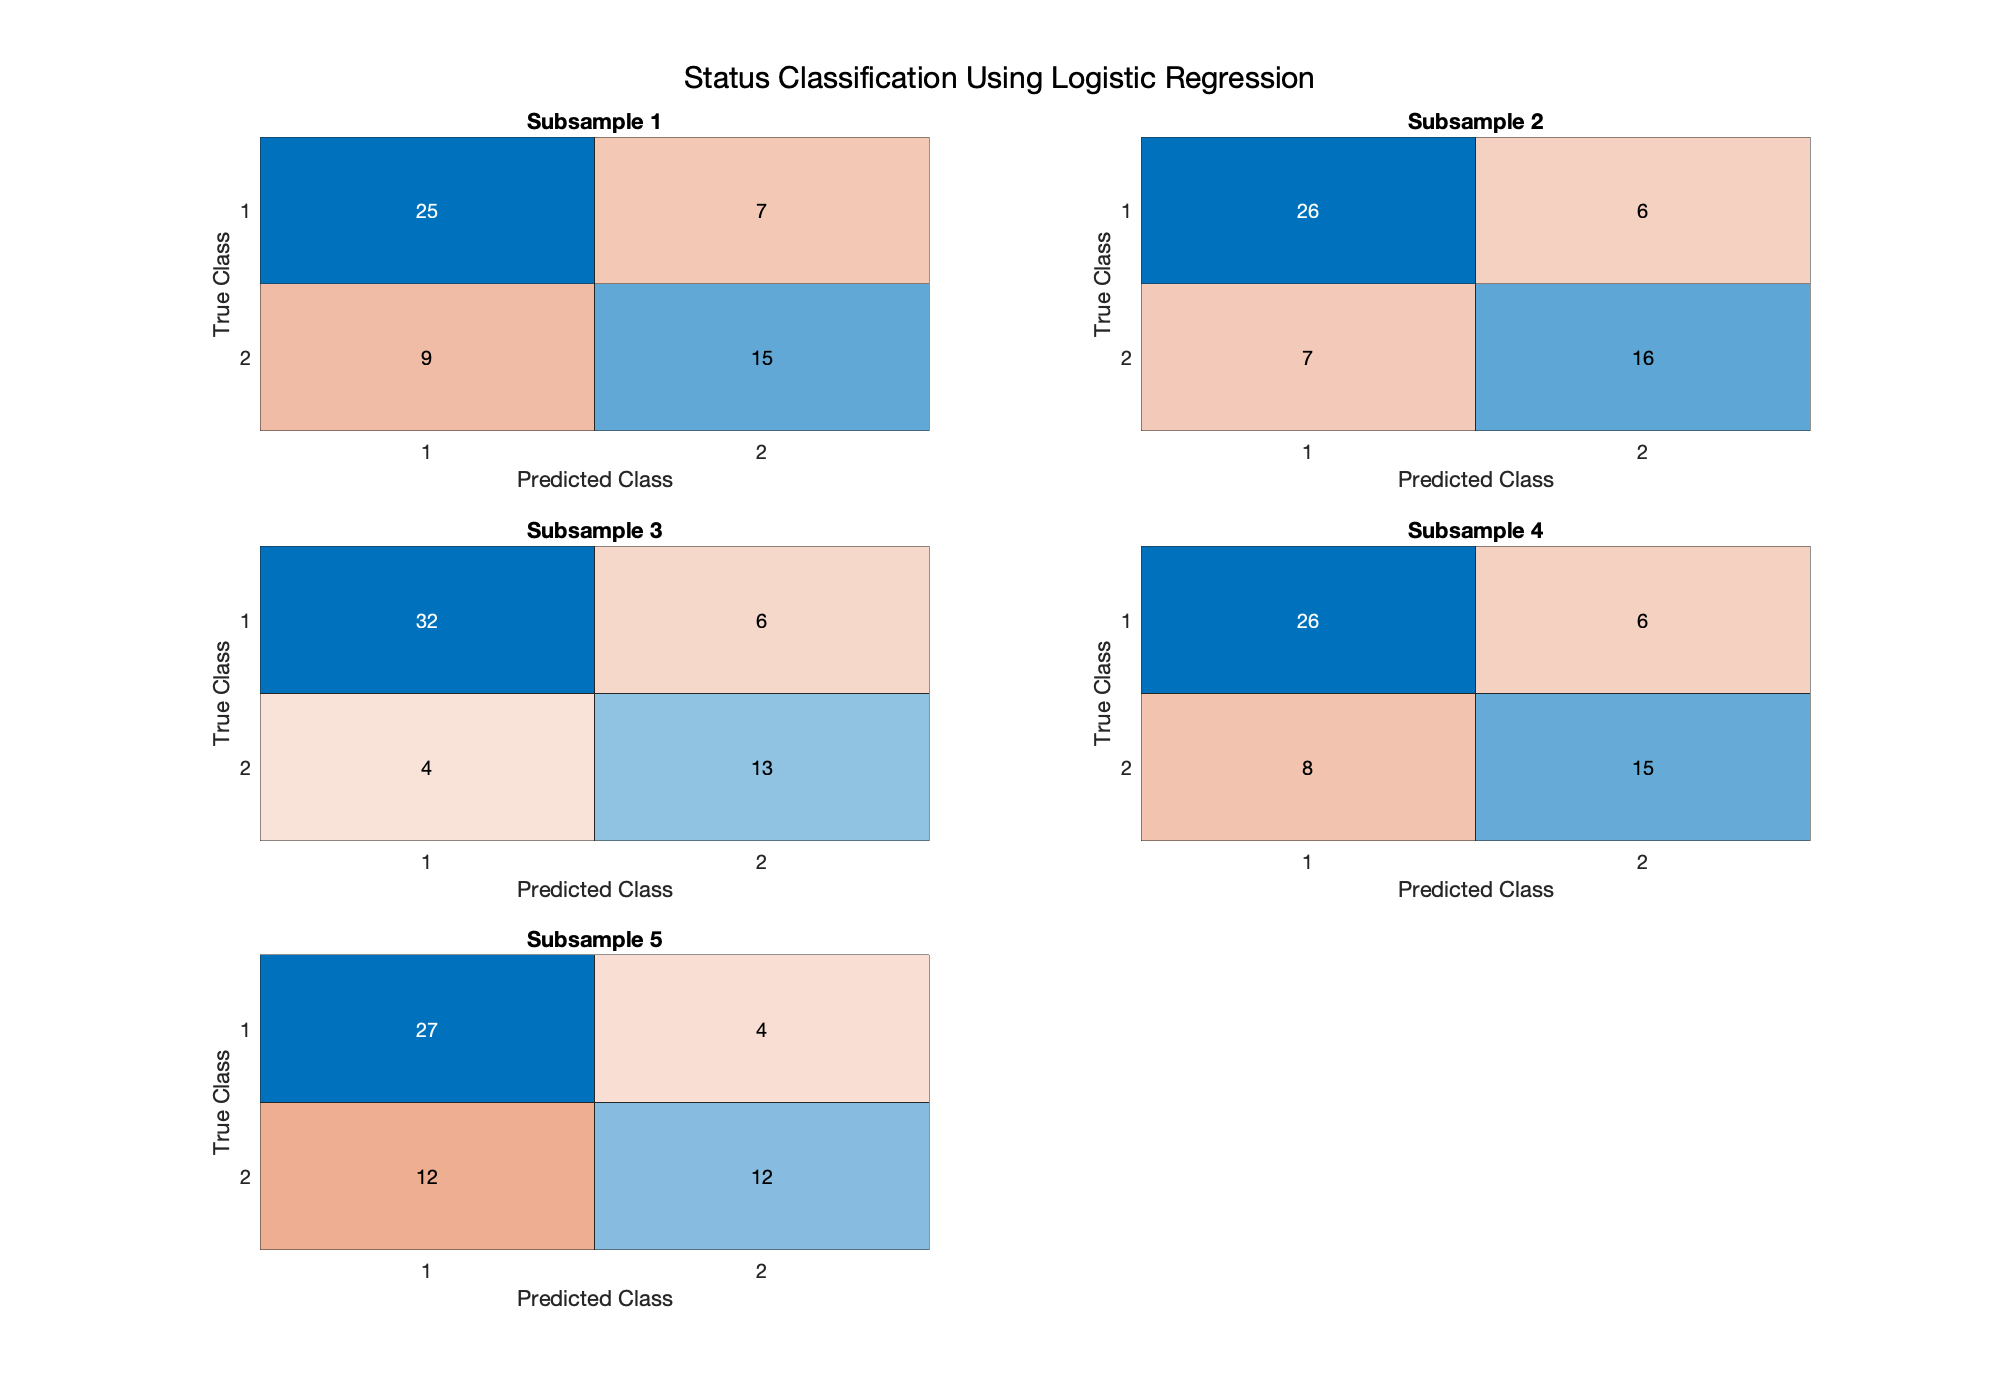

f = figure();
set(f, 'Position', expandFigSize)
for i=1:NFolds
    subplot(ceil(NFolds/2),floor(NFolds/2),i)
    cm = confusionchart(regressionModel.logist.confusion{i});
    cm.Title = sprintf("Subsample %d",i);
end
sgtitle("Status Classification Using Logistic Regression")

T = table();
for i=1:NFolds
    tempT = table([regressionModel.logist.bestFeaturesNames{i},...
        num2cell(regressionModel.logist.bestFeaturesCoeff{i})],...
        'VariableNames',cellstr(sprintf("Subset %i",i)));
    T = [T tempT];
end
T

T = 8×5 table
               Subset 1                        Subset 2                      Subset 3                      Subset 4                      Subset 5          
    ______________________________    __________________________    __________________________    __________________________    ___________________________

    {'age'    }    {[    88.8792]}    {'alkphos'}    {[-7.2926]}    {'age'    }    {[22.5655]}    {'alkphos'}    {[-6.7341]}    {'age'    }    {[113.5512]}
    {'alkphos'}    {[    -3.9411]}    {'age'    }    {[79.1033]}    {'alkphos'}    {[-6.3837]}    {'age'    }    {[58.3636]}    {'logpro' }    {[ -0.5337]}
    {'logpro' }    {[    -0.5764]}    {'logpro' }    {[-0.5537]}    {'ast'    }    {[ 0.2563]}    {'copper' }    {[-0.0025]}    {'protime'}    {[ -0.0016]}
    {'ast'    }    {[     0.5772]} 

## Task 7 - Random Forest Model

### Tree Bagger Time Regression

Used cirrhosis_log again because it's regression.

for i=1:NFolds
    test = (indices == i);
    train = ~test;
    % Extract train rows from X and Y
    trainData = cirrhosis_log(train,:);
    Xtrain = table2array(trainData(:,1:end-1));
    Ytrain = table2array(trainData(:,end));
    % Extract test rows from X and Y
    testData = cirrhosis_log(test,:);
    Xtest = table2array(testData(:,1:end-1));
    Ytest = table2array(testData(:,end));
    
    % Create linear model with train data.
    rfMdlTime = TreeBagger(100,Xtrain,Ytrain,'Method','regression','OOBPrediction','On','OOBPredictorImportance','on');
    Ypred = rfMdlTime.predict(Xtest);
    
    % Evaluate the model
    regressionModel.rfMdlTime.fit{i} = rfMdlTime;
    regressionModel.rfMdlTime.absError(i) = mean(abs(Ypred-Ytest));
    [regressionModel.rfMdlTime.corrR(i),regressionModel.rfMdlTime.corrP(i)] = corr(Ytest,Ypred);
    [regressionModel.rfMdlTime.rankCorrR(i),regressionModel.rfMdlTime.rankCorrP(i)] = corr(Ytest,Ypred,'Type','Spearman');
end

### Tree Bagger Time Regression Analysis

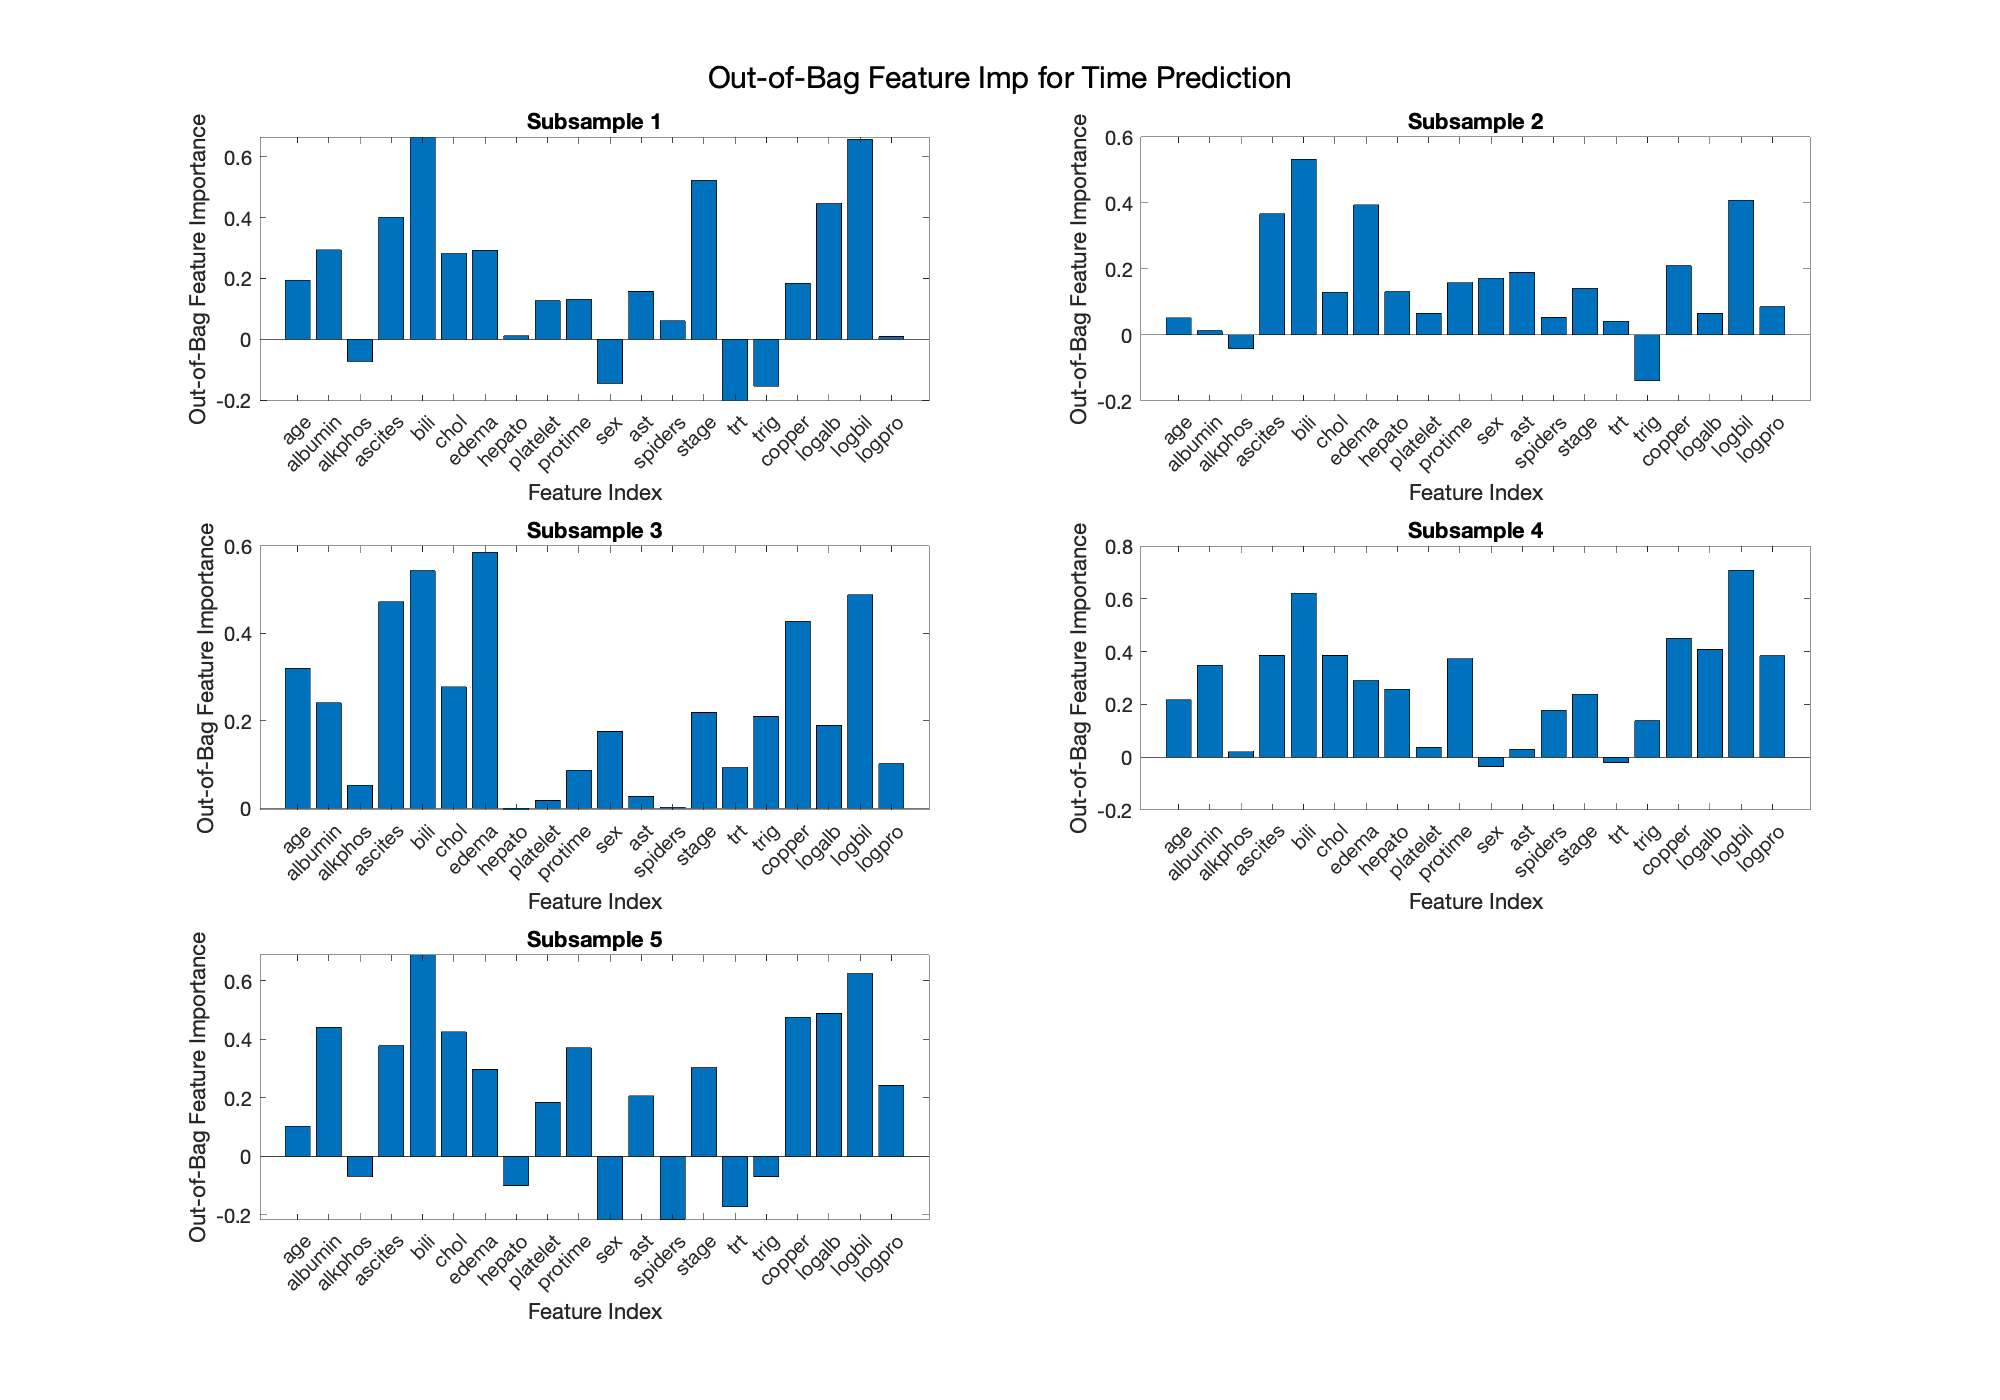

f = figure();
set(f, 'Position', expandFigSize)
for i=1:NFolds
    subplot(ceil(NFolds/2),floor(NFolds/2),i)
    bar(regressionModel.rfMdlTime.fit{i}.OOBPermutedPredictorDeltaError)
    xlabel('Feature Index')
    ylabel('Out-of-Bag Feature Importance')
    title(sprintf('Subsample %i',i))
    xticks(1:length(cirrhosis_log_names)-1)
    xticklabels(cirrhosis_log_names(1:end-1))
    xtickangle(45)
end
sgtitle('Out-of-Bag Feature Imp for Time Prediction')

rfVarNames = ["Average Absolute Error","Pearsons Correlation",...
    "Pearsons Correlation P-val","Rank Correlation", "Rank Correlation P-val"];
table(regressionModel.rfMdlTime.absError',regressionModel.rfMdlTime.corrR',...
    regressionModel.rfMdlTime.corrP',regressionModel.rfMdlTime.rankCorrR',regressionModel.rfMdlTime.rankCorrP',...
    'VariableNames', rfVarNames,'RowNames', rowNames)

ans = 5×5 table
                   Average Absolute Error    Pearsons Correlation    Pearsons Correlation P-val    Rank Correlation    Rank Correlation P-val
                   ______________________    ____________________    __________________________    ________________    ______________________

    Subsample 1           0.43675                  0.68483                   5.8558e-09                0.56539               5.6194e-06      
    Subsample 2           0.49871                  0.83679                   1.7666e-15                0.70931               1.7963e-09      
    Subsample 3           0.36319                  0.76693                   8.6572e-12                 0.6246                 6.81e-07      
    Subsample 4           0.52336  

### Tree Bagger Status Classification

accuracyGuess = zeros(100,NFolds);
meanGuess = zeros(NFolds,1);
sigDiff = zeros(NFolds,2);

for i=1:NFolds
    test = (indices == i);
    train = ~test;
    % Extract train rows from X and Y
    trainData = cirrhosis_status(train,:);
    Xtrain = table2array(trainData(:,1:end-1));
    Ytrain = table2array(trainData(:,end));
    % Extract test rows from X and Y
    testData = cirrhosis_status(test,:);
    Xtest = table2array(testData(:,1:end-1));
    Ytest = double(table2array(testData(:,end)));

    % Create linear model with train data.
    rfMdlStatus = TreeBagger(100,Xtrain,Ytrain,'OOBPrediction','On','OOBPredictorImportance','on');
    Ypred = double(categorical(rfMdlStatus.predict(Xtest))) - 1;
    
     %Comparing model to 100 random guesses
    for k = 1:100
        random_pred = Ytrain(randperm(length(Ytest)));
        accuracyGuess(k,i) = sum(random_pred == Ytest)/length(Ytest);        
    end
    meanGuess(i) = mean(accuracyGuess(:,i));
    
    accuracy = sum(Ypred == Ytest)/length(Ypred);
    %T test comparing model accuracy to random guess accuracy
    [sigDiff(i,1),sigDiff(i,2)] = ttest2(accuracy,accuracyGuess(:,i));
    meanGuessError = meanGuess(i) - accuracy;
    
    % Evaluate the model
    regressionModel.rfMdlStatus.fit{i} = rfMdlStatus;
    regressionModel.rfMdlStatus.confusion{i} = confusionmat(Ytest,Ypred);
    regressionModel.rfMdlStatus.absError(i)  = mean(abs(Ypred-Ytest));
    regressionModel.rfMdlStatus.accuracy(i)  = accuracy;
    [regressionModel.rfMdlStatus.corrR(i),regressionModel.rfMdlStatus.corrP(i)] = corr(Ytest,Ypred);
    [regressionModel.rfMdlStatus.rankCorrR(i),regressionModel.rfMdlStatus.rankCorrP(i)] = corr(Ytest,Ypred,'Type','Spearman');
    regressionModel.rfMdlStatus.meanGuessError(i) = meanGuessError;
    regressionModel.rfMdlStatus.compareGuess(i) = sigDiff(i,2);
end

### Tree Bagger Status Classification Analysis

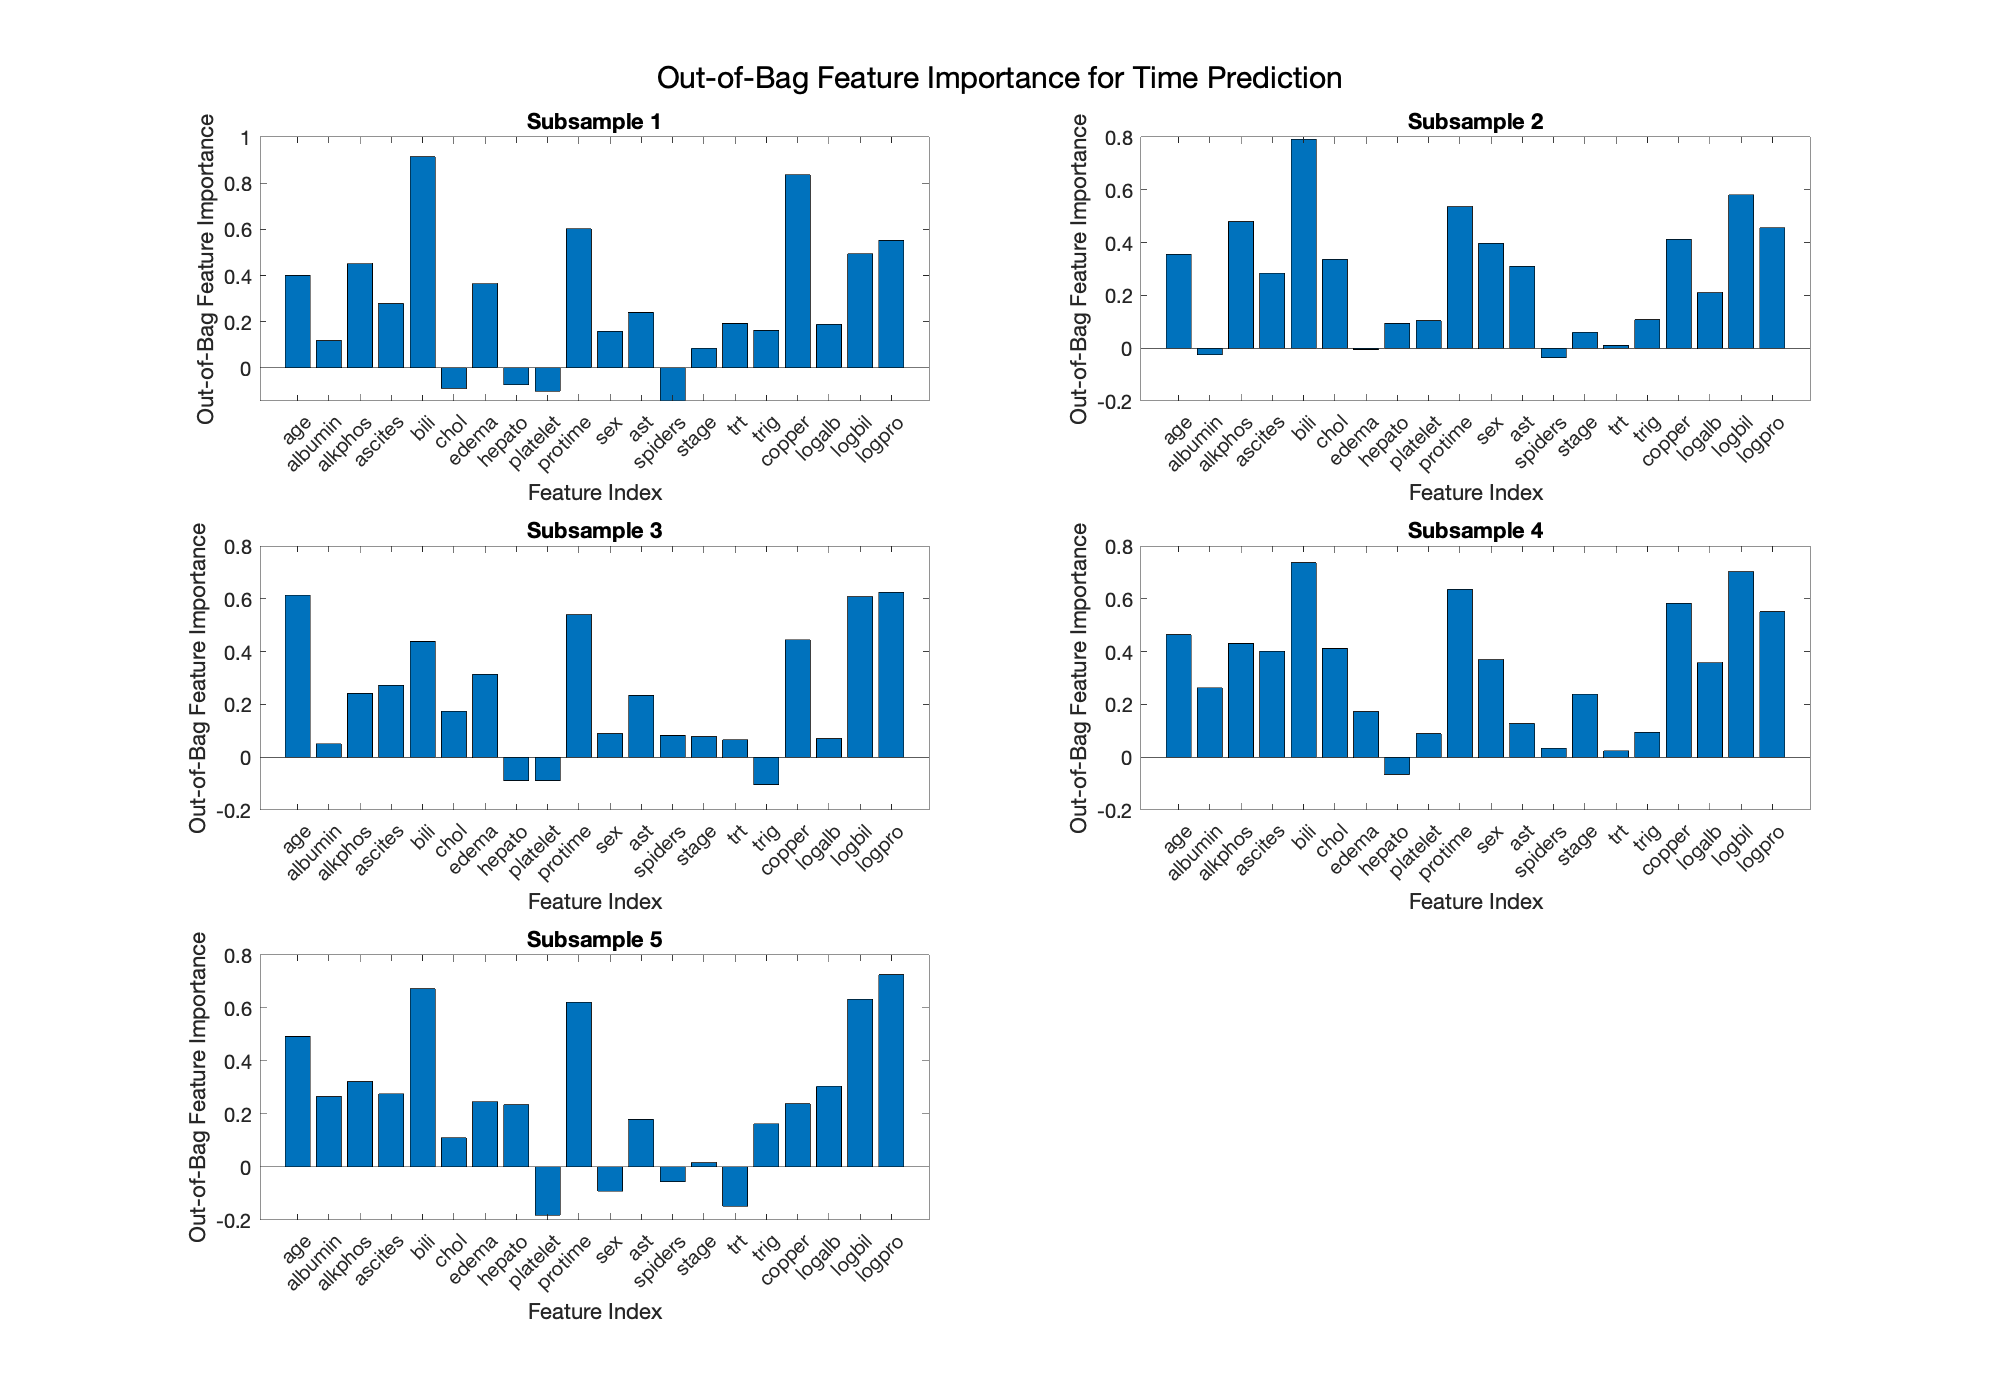

f = figure();
set(f, 'Position', expandFigSize)
for i=1:NFolds
    subplot(ceil(NFolds/2),floor(NFolds/2),i)
    bar(regressionModel.rfMdlStatus.fit{i}.OOBPermutedPredictorDeltaError)
    xlabel('Feature Index')
    ylabel('Out-of-Bag Feature Importance')
    title(sprintf('Subsample %i',i))
    xticks(1:length(cirrhosis_status_names)-1)
    xticklabels(cirrhosis_status_names(1:end-1))
    xtickangle(45)
end
sgtitle('Out-of-Bag Feature Importance for Time Prediction')

rfClassVarNames = ["Average Absolute Error","Accuracy","Pearsons Correlation",...
    "Pearsons Correlation P-val","Rank Correlation", "Rank Correlation P-val","Mean Guess Error","Guess Difference"];
table(regressionModel.rfMdlStatus.absError',regressionModel.rfMdlStatus.accuracy',regressionModel.rfMdlStatus.corrR',...
    regressionModel.rfMdlStatus.corrP',regressionModel.rfMdlStatus.rankCorrR',regressionModel.rfMdlStatus.rankCorrP',...
    regressionModel.rfMdlStatus.meanGuessError',regressionModel.rfMdlStatus.compareGuess', ...
    'VariableNames',rfClassVarNames,'RowNames', rowNames)

ans = 5×8 table
                   Average Absolute Error    Accuracy    Pearsons Correlation    Pearsons Correlation P-val    Rank Correlation    Rank Correlation P-val    Mean Guess Error    Guess Difference
                   ______________________    ________    ____________________    __________________________    ________________    ______________________    ________________    ________________

    Subsample 1           0.21429            0.78571           0.55943                   7.3925e-06                0.55943               7.3925e-06              -0.30179           2.5952e-07   
    Subsample 2               0.2                0.8           0.60004                   1.2862

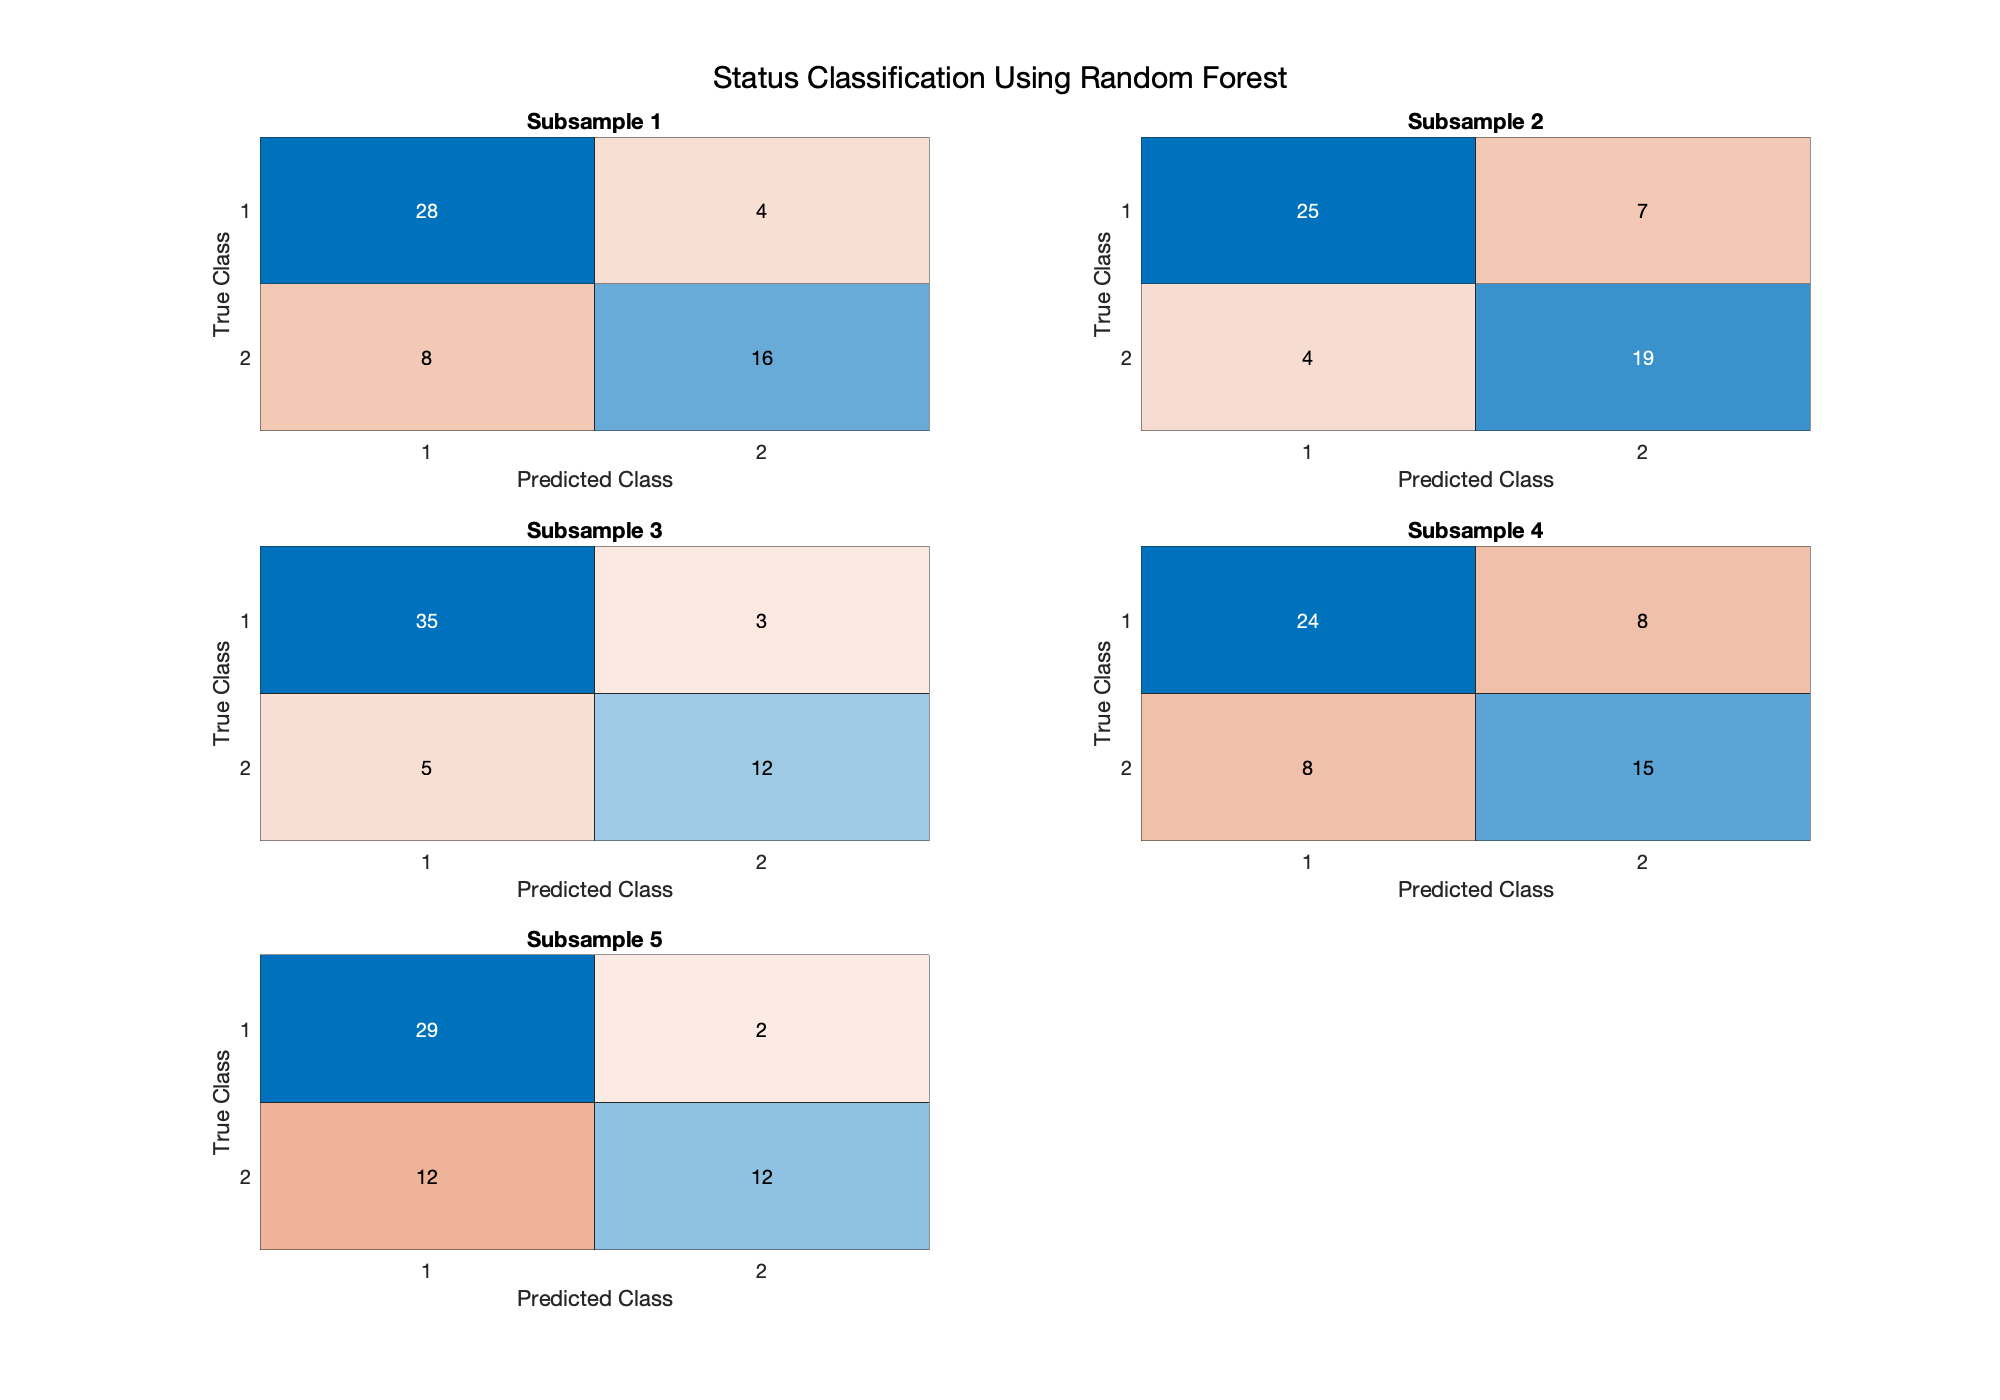

f = figure();
set(f, 'Position', expandFigSize)
for i=1:NFolds
    subplot(ceil(NFolds/2),floor(NFolds/2),i)
    cm = confusionchart(regressionModel.rfMdlStatus.confusion{i});
    cm.Title = sprintf("Subsample %d",i);
end
sgtitle("Status Classification Using Random Forest")

### Task 8 - **New Machine Learning Algorithm: Support Vector Machiine**

For predicting status - binary classification

for i=1:NFolds
    test = (indices == i);
    train = ~test;
    % Extract train rows from X and Y
    trainData = cirrhosis_status(train,:);
    Xtrain = table2array(trainData(:,1:end-1));
    Ytrain = table2array(trainData(:,end));
    % Extract test rows from X and Y
    testData = cirrhosis_status(test,:);
    Xtest = table2array(testData(:,1:end-1));
    Ytest = double(table2array(testData(:,end)));
    
    svmMdlStatus = fitcsvm(cirrhosis_status,'status');
    Ypred = double(categorical(svmMdlStatus.predict(Xtest))) - 1;
    
   
     %Comparing model to 100 random guesses
    for k = 1:100
        random_pred = Ytrain(randperm(length(Ytest)));
        accuracyGuess(k,i) = sum(random_pred == Ytest)/length(Ytest);        
    end
    meanGuess(i) = mean(accuracyGuess(:,i));
    
    accuracy = sum(Ypred == Ytest)/length(Ypred);  
    
    %T test comparing model accuracy to random guess accuracy
    [sigDiff(i,1),sigDiff(i,2)] = ttest2(accuracy,accuracyGuess(:,i));
    meanGuessError = meanGuess(i) - accuracy;
    
    % Evaluate the model
    regressionModel.svmMdlStatus.fit{i} = svmMdlStatus;
    regressionModel.svmMdlStatus.confusion{i} = confusionmat(Ytest,Ypred);
    regressionModel.svmMdlStatus.absError(i)  = mean(abs(Ypred-Ytest));
    regressionModel.svmMdlStatus.accuracy(i)  = accuracy;
    [regressionModel.svmMdlStatus.corrR(i),regressionModel.svmMdlStatus.corrP(i)] = corr(Ytest,Ypred);
    [regressionModel.svmMdlStatus.rankCorrR(i),regressionModel.svmMdlStatus.rankCorrP(i)] = corr(Ytest,Ypred,'Type','Spearman');
    regressionModel.svmMdlStatus.meanGuessError(i) = meanGuessError;
    regressionModel.svmMdlStatus.compareGuess(i) = sigDiff(i,2);
end

svmClassVarNames = ["Average Absolute Error","Accuracy","Pearsons Correlation",...
    "Pearsons Correlation P-val","Rank Correlation", "Rank Correlation P-val","Mean Guess Error","Guess Difference"];
table(regressionModel.svmMdlStatus.absError',regressionModel.svmMdlStatus.accuracy',regressionModel.svmMdlStatus.corrR',...
    regressionModel.svmMdlStatus.corrP',regressionModel.svmMdlStatus.rankCorrR',regressionModel.svmMdlStatus.rankCorrP',...
    regressionModel.svmMdlStatus.meanGuessError',regressionModel.svmMdlStatus.compareGuess', ...
    'VariableNames',svmClassVarNames,'RowNames', rowNames)

ans = 5×8 table
                   Average Absolute Error    Accuracy    Pearsons Correlation    Pearsons Correlation P-val    Rank Correlation    Rank Correlation P-val    Mean Guess Error    Guess Difference
                   ______________________    ________    ____________________    __________________________    ________________    ______________________    ________________    ________________

    Subsample 1              0.25               0.75           0.48412                   0.00015657                0.48412               0.00015657              -0.28143           1.4628e-06   
    Subsample 2           0.21818            0.78182           0.55678                   1.0123

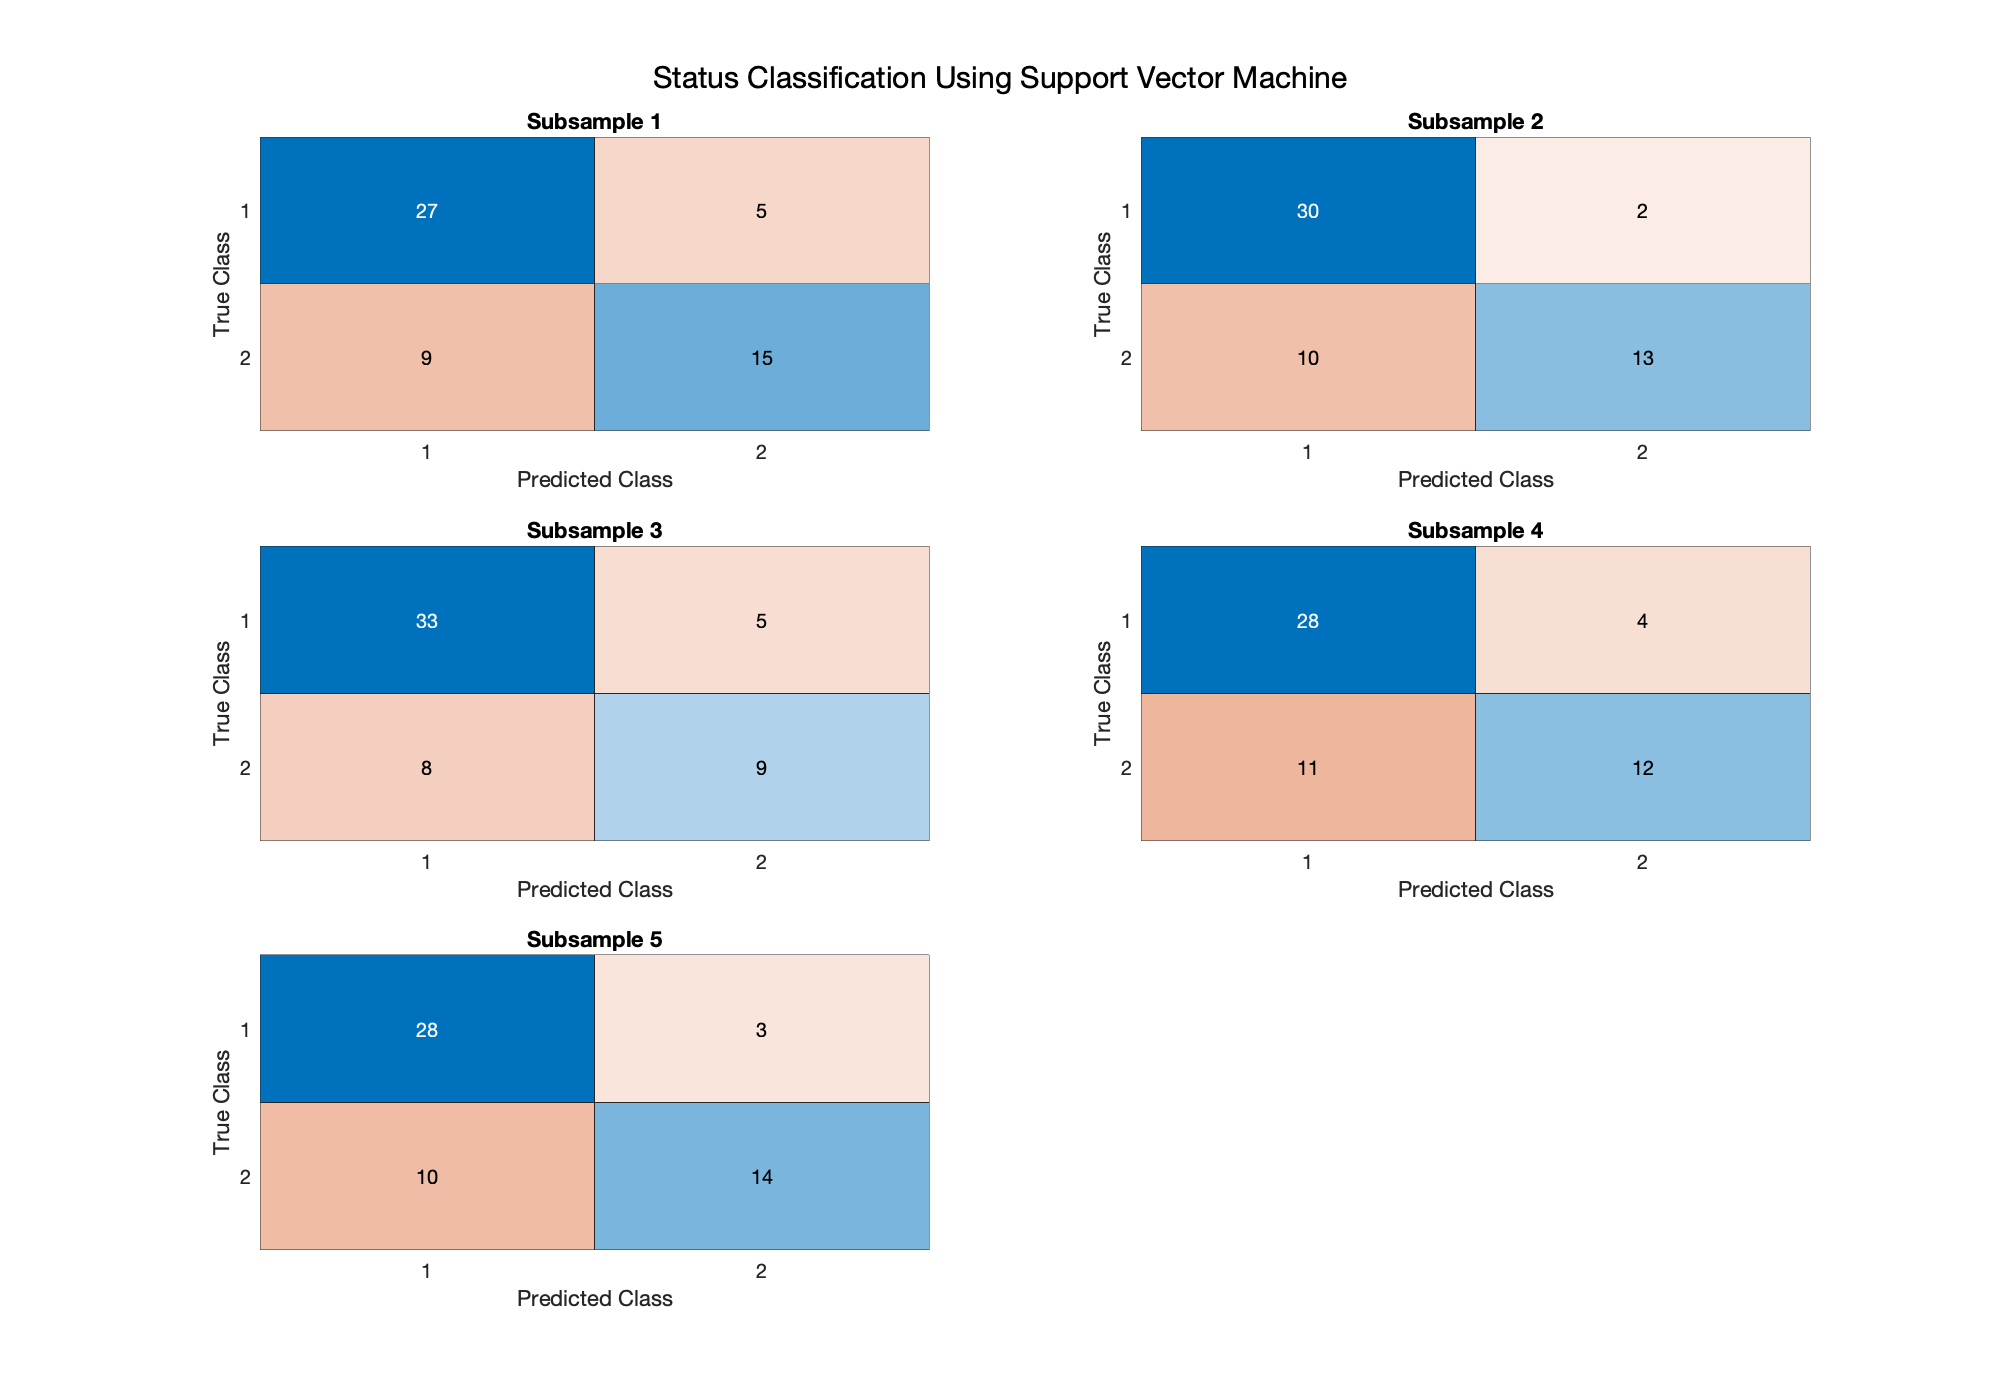

f = figure();
set(f, 'Position', expandFigSize)
for i=1:NFolds
    subplot(ceil(NFolds/2),floor(NFolds/2),i)
    cm = confusionchart(regressionModel.svmMdlStatus.confusion{i});
    cm.Title = sprintf("Subsample %d",i);
end
sgtitle("Status Classification Using Support Vector Machine")

### Task 9 - Status Logistic vs Random Forest vs SVM

compVarNames = ["Logistic","Random Forest", "Support Vector Machine (SVM)"];
compRowNames = ["Pearsons Correlation","Mean Absolute Error","Accuracy"];
compData = [
    mean(regressionModel.logist.corrR),    mean(regressionModel.rfMdlStatus.corrR),    mean(regressionModel.svmMdlStatus.corrR)
    mean(regressionModel.logist.absError), mean(regressionModel.rfMdlStatus.absError), mean(regressionModel.svmMdlStatus.absError)
    mean(regressionModel.logist.accuracy), mean(regressionModel.rfMdlStatus.accuracy), mean(regressionModel.svmMdlStatus.accuracy)
];
table(compData(:,1),compData(:,2), compData(:,3),...
        'VariableNames', compVarNames,'RowNames', compRowNames)

ans = 3×3 table
                            Logistic    Random Forest    Support Vector Machine (SVM)
                            ________    _____________    ____________________________

    Pearsons Correlation    0.47797        0.54159                  0.4832           
    Mean Absolute Error     0.24987        0.22104                 0.24273           
    Accuracy                0.75013        0.77896                 0.75727           


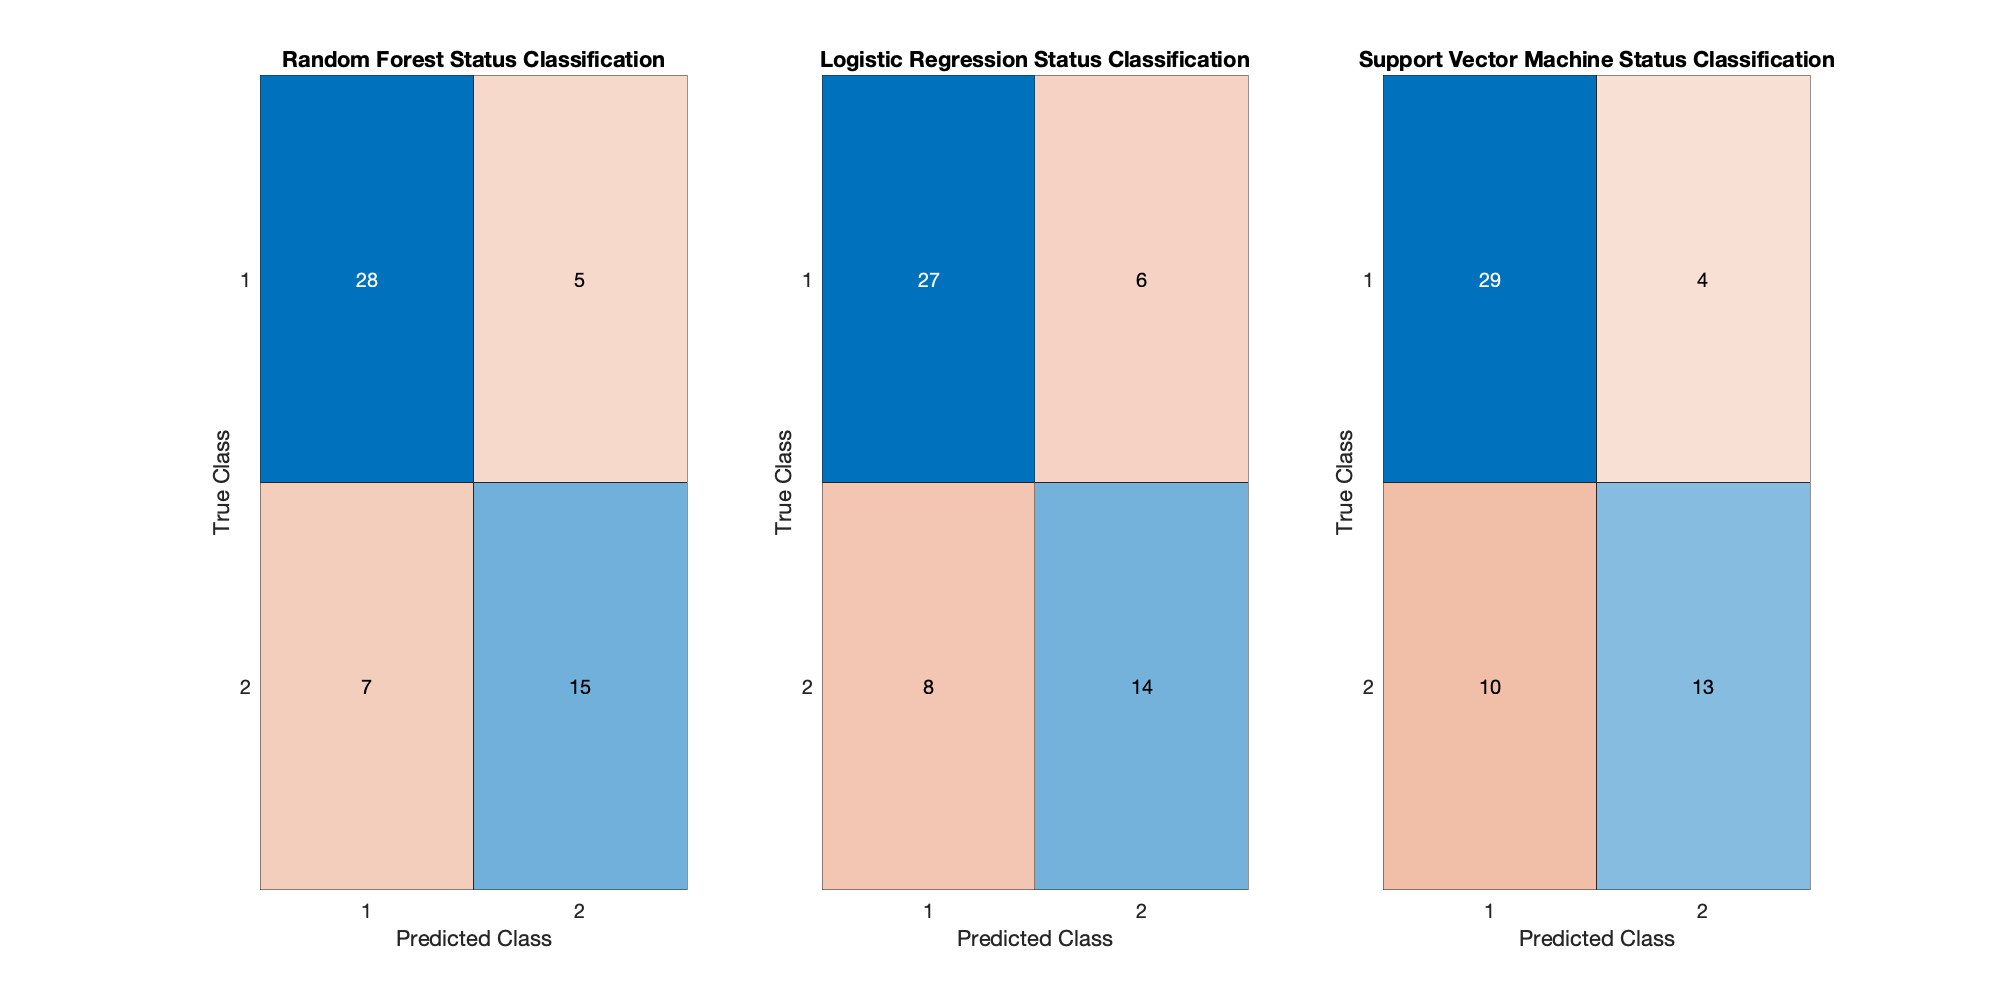

f = figure();
set(f, 'Position', [0,0,1000,500])
subplot(1,3,1)
confusionchart(round(mean(cat(3,regressionModel.rfMdlStatus.confusion{:}),3)));
title("Random Forest Status Classification")
subplot(1,3,2)
confusionchart(round(mean(cat(3,regressionModel.logist.confusion{:}),3)));
title("Logistic Regression Status Classification")
subplot(1,3,3)
confusionchart(round(mean(cat(3,regressionModel.svmMdlStatus.confusion{:}),3)));
title("Support Vector Machine Status Classification")